# LAB2 - MATHEMATICAL MODEL: NEURONAL MEMBRANE DYNAMICS

#### Carla Berard González, Marta Manzano Balsells, Lola Martínez Pedraza

In this lab, we use the Hodgkin–Huxley model to study how an external current changes the membrane potential of a neuron. The model includes sodium, potassium and leakage currents, together with the membrane capacitance. 

We build it in Simulink and compared the response to four types of input. We also test how changing the membrane parameters affects the simulated response.

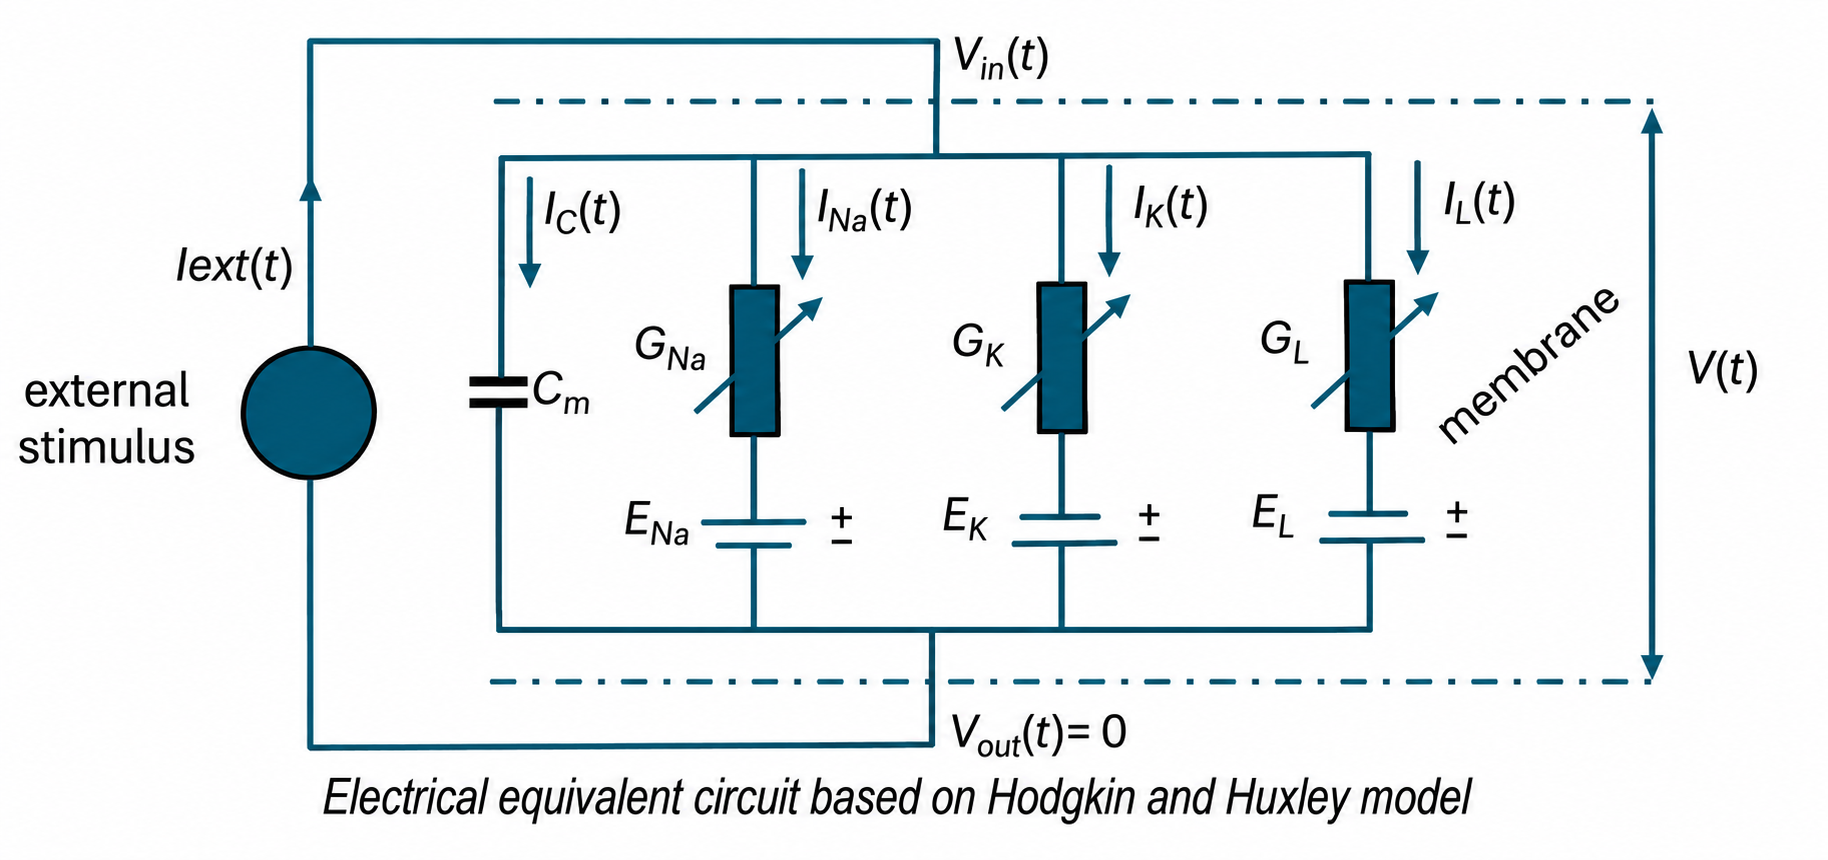

%% LAB 2 - Hodgkin-Huxley Model
clear;
clc;
close all;

%% Equilibrium potentials [mV]
ENa = 115;       % Sodium
EK  = -12;       % Potassium
EL  = 10.613;    % Leakage

%% Maximum conductances [mS/cm^2]
GNa = 120;       % Sodium conductance
GK  = 36;        % Potassium conductance
Gl  = 0.3;       % Leakage conductance

%% Membrane capacitance [uF/cm^2]
Cm = 1;

%% Initial conditions
V0 = 0;          % Membrane potential [mV]
m0 = 0;          % Sodium activation
h0 = 0;          % Sodium inactivation
n0 = 0;          % Potassium activation

%% External current
Iamp = 10;       % Current amplitude [uA/cm^2]

%% Random signal parameters
seed_rand = 1;    % Seed for reproducible random signals
var_rand = 3;     % Variance
mean_rand = 10;   % Mean current [uA/cm^2]
step_amplitude = 30;     % from 0 to 200

%% Simulation time
Tstop = 5;     % Time [ms]

disp('Hodgkin-Huxley parameters loaded successfully');

Hodgkin-Huxley parameters loaded successfully


**1- Implement the model in Simulink and use MATLAB to define parameters, add model information and comments, and plot the signals (scope block for verification): V(t), IL(t), INa(t), IK(t), m(t), h(t), n(t).**

For this section, we first divided it into different parts corresponding to the gating variables, ionic conductances, ionic currents and membrane potential. 

Each part uses the results from the previous calculations, while the membrane voltage is fed back into the model because it also determines how the ion channels behave.

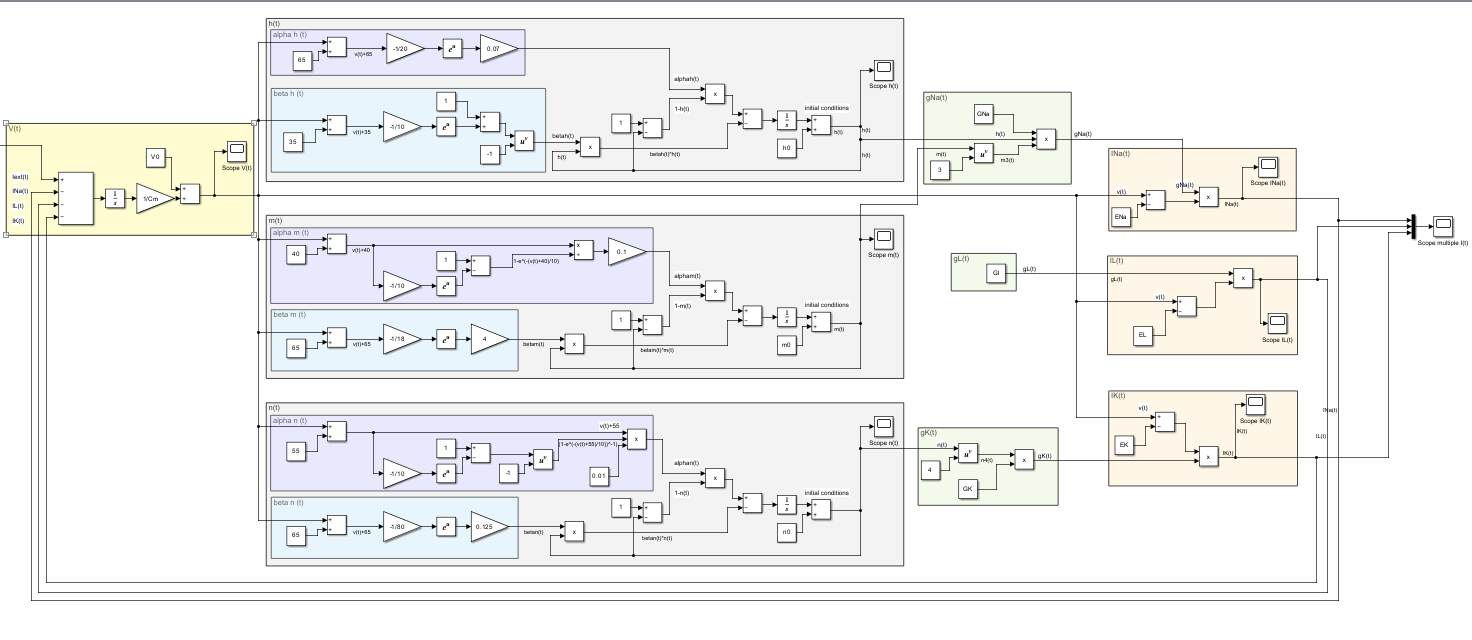

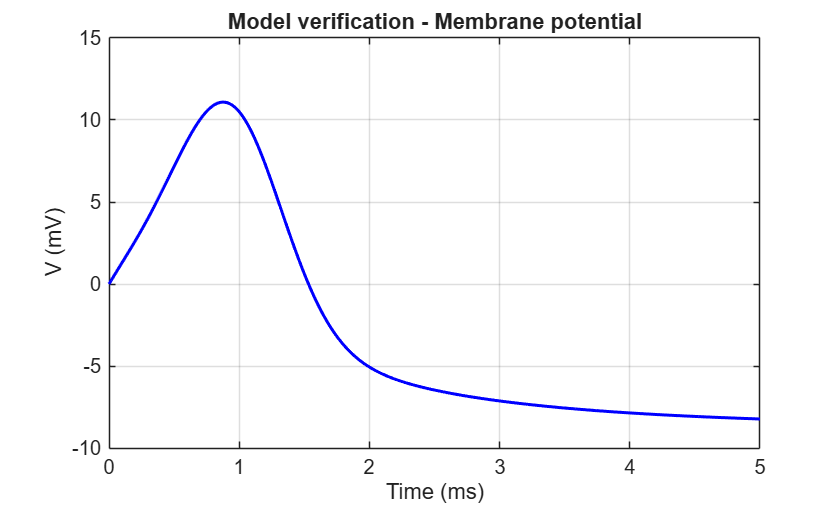

% model verification step
input_selector = 1; 

% Sine input parameters
A_sine = 10;
bias_sine = 5;
w_sine = 10;

%% Model verification - 3 plots

% Run verification with the original parameters
out_ver = sim('circuit', 'StopTime', string(Tstop));

% Extract the seven signals
V   = out_ver.V.get(1).Values;
INa = out_ver.INa.get(1).Values;
IK  = out_ver.IK.get(1).Values;
IL  = out_ver.IL.get(1).Values;
m   = out_ver.m.get(1).Values;
h   = out_ver.h.get(1).Values;
n   = out_ver.n.get(1).Values;

%% Plot 1 - Membrane potential V(t)
figure;
plot(V.Time, V.Data, 'b', 'LineWidth', 1.5);
xlabel('Time (ms)');
ylabel('V (mV)');
title('Model verification - Membrane potential');
grid on;

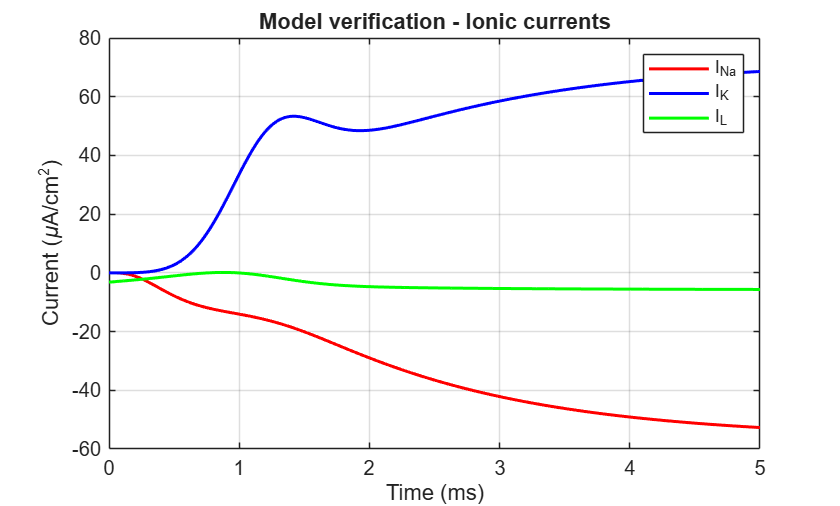


%% Plot 2 - Ionic currents
figure;
plot(INa.Time, INa.Data, 'r', 'LineWidth', 1.5);
hold on;
plot(IK.Time, IK.Data, 'b', 'LineWidth', 1.5);
plot(IL.Time, IL.Data, 'g', 'LineWidth', 1.5);
hold off;

xlabel('Time (ms)');
ylabel('Current (\muA/cm^2)');
title('Model verification - Ionic currents');
legend('I_{Na}', 'I_K', 'I_L');
grid on;

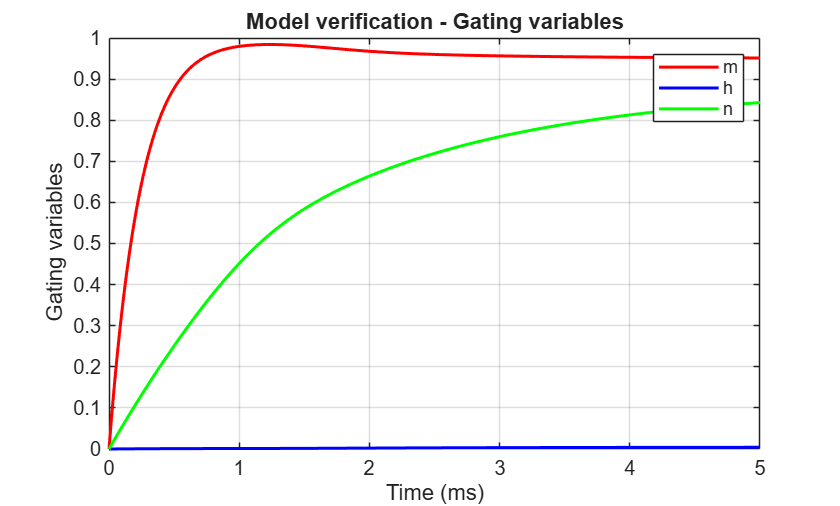


%% Plot 3 - Gating variables
figure;
plot(m.Time, m.Data, 'r', 'LineWidth', 1.5);
hold on;
plot(h.Time, h.Data, 'b', 'LineWidth', 1.5);
plot(n.Time, n.Data, 'g', 'LineWidth', 1.5);
hold off;

xlabel('Time (ms)');
ylabel('Gating variables');
title('Model verification - Gating variables');
legend('m', 'h', 'n');
grid on;

**2- Construct an effective conceptual model.**

The conceptual model helps us understand how the different parts of the circuit are related without looking at every individual Simulink block. We can see that the membrane potential V(t) is used to calculate the three gating variables: m(t), which represents sodium channel activation; h(t), which represents sodium channel inactivation; and n(t), which represents potassium channel activation.

These variables are then used to obtain the sodium and potassium conductances, while the leakage conductance remains constant. From these conductances and the membrane voltage, we calculate the three ionic currents, which are combined with the external current to obtain the new value of V(t). This voltage is then fed back into the system, allowing the model to update continuously throughout the simulation.

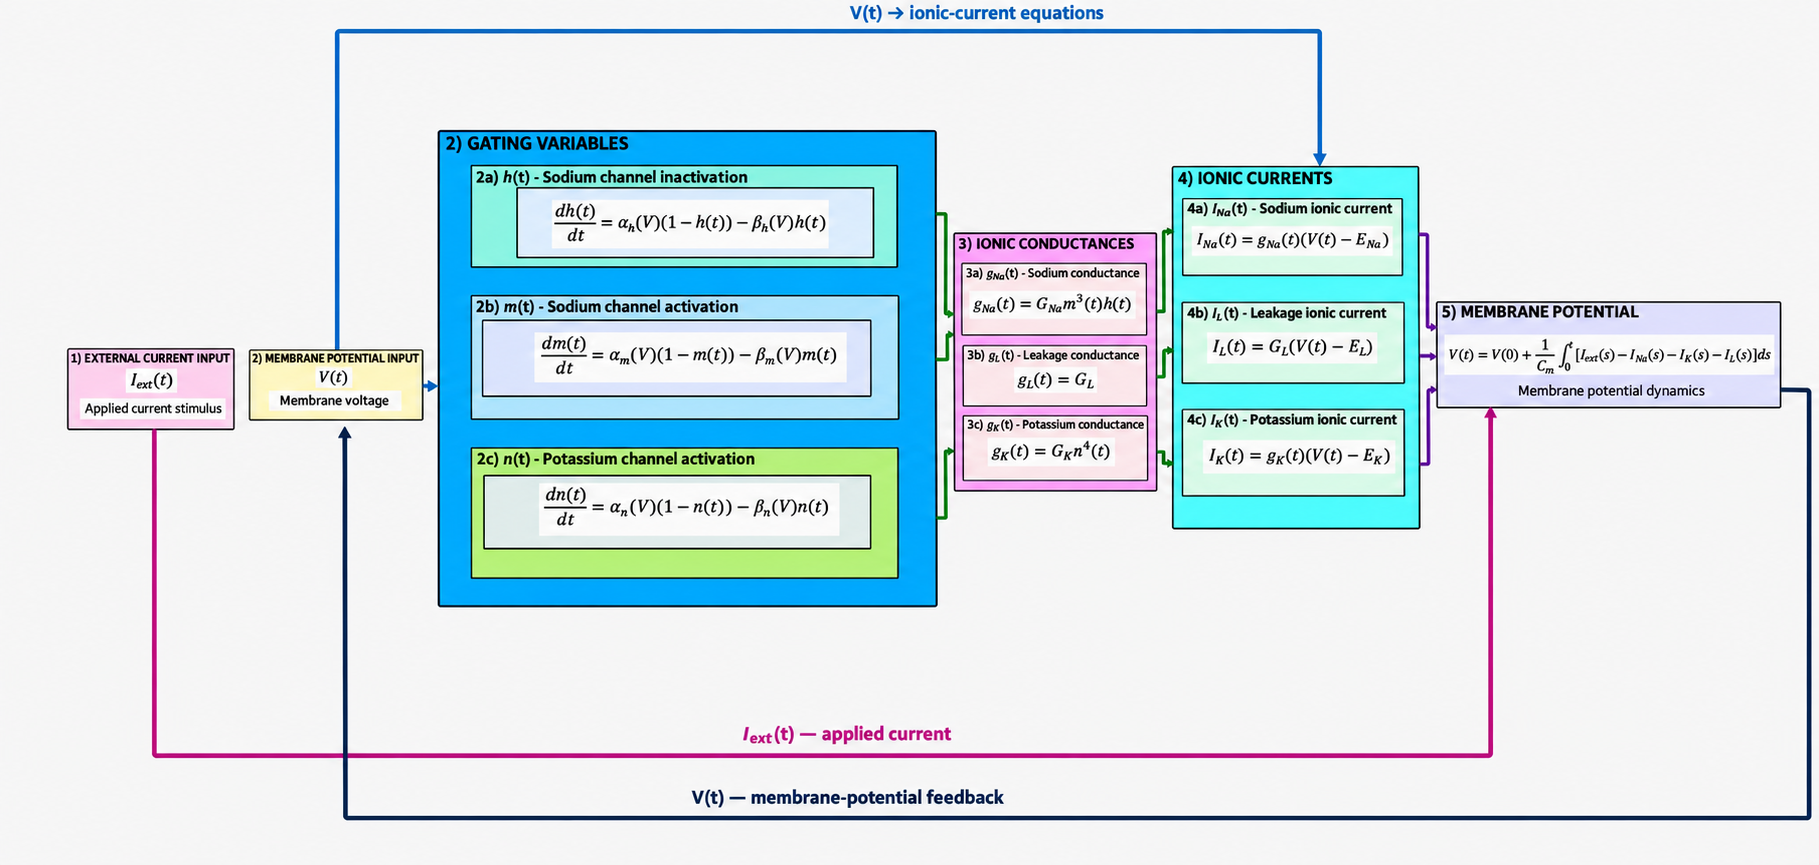

**3- Consider input Iext(t) such as:**

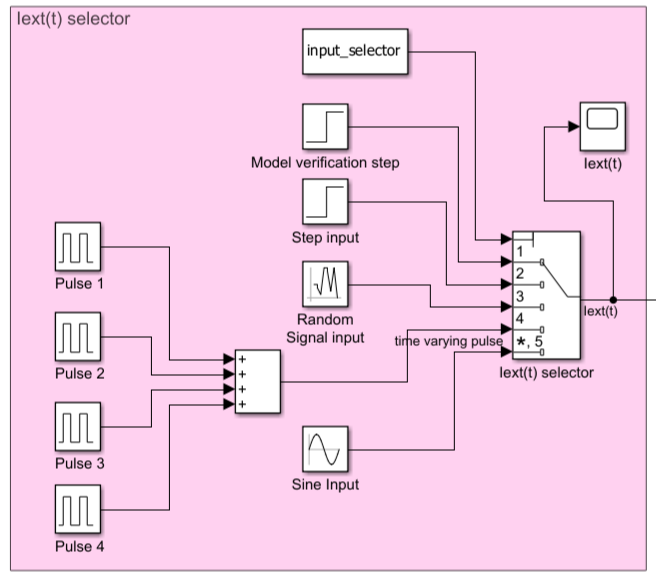

%% Parameters for physiological simulations
ENa = 50;
EK  = -77;
EL  = -54.4;

V0 = -65;
m0 = 0.0529;
h0 = 0.5961;
n0 = 0.3177;

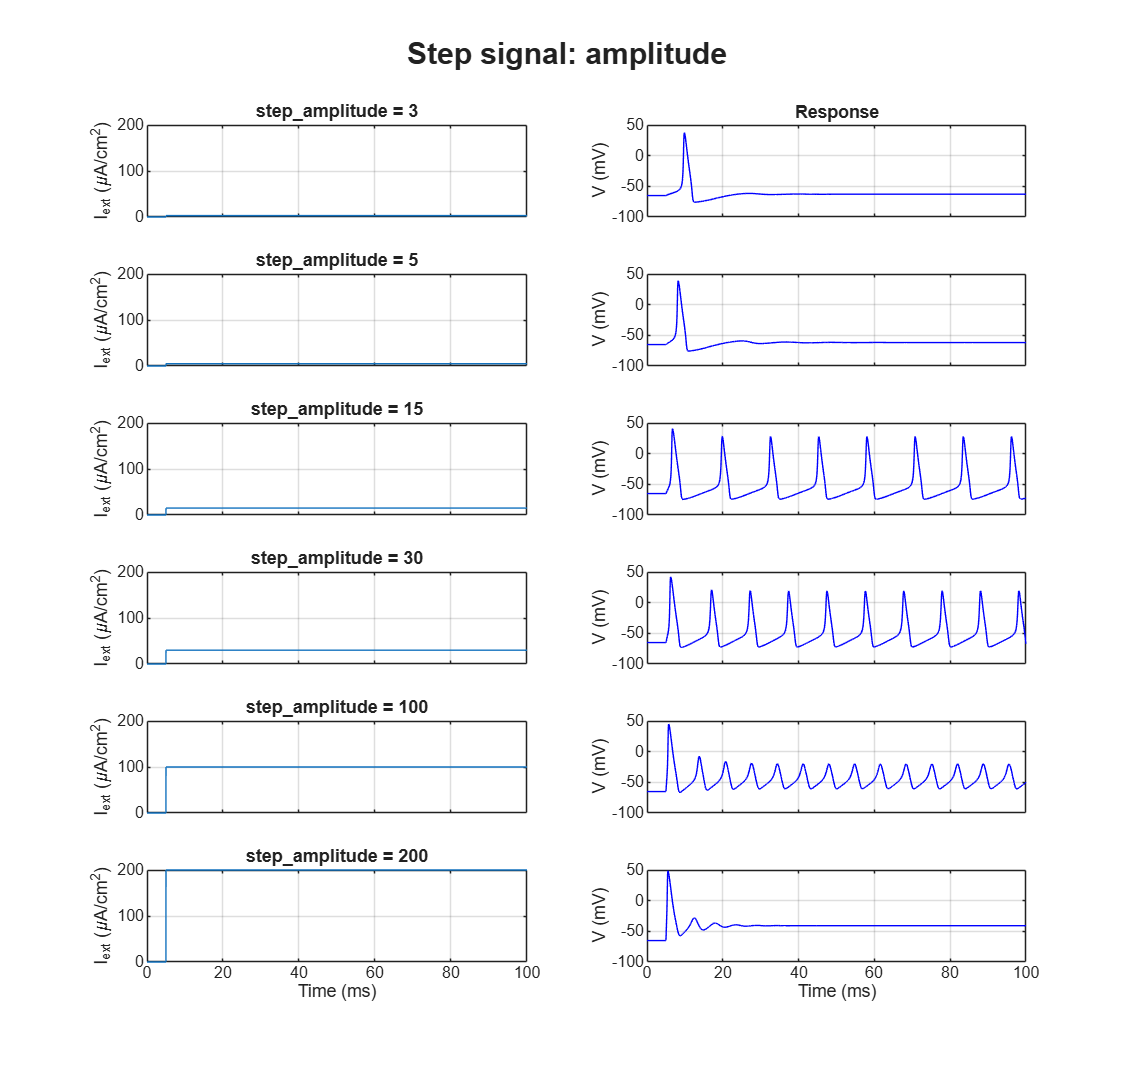

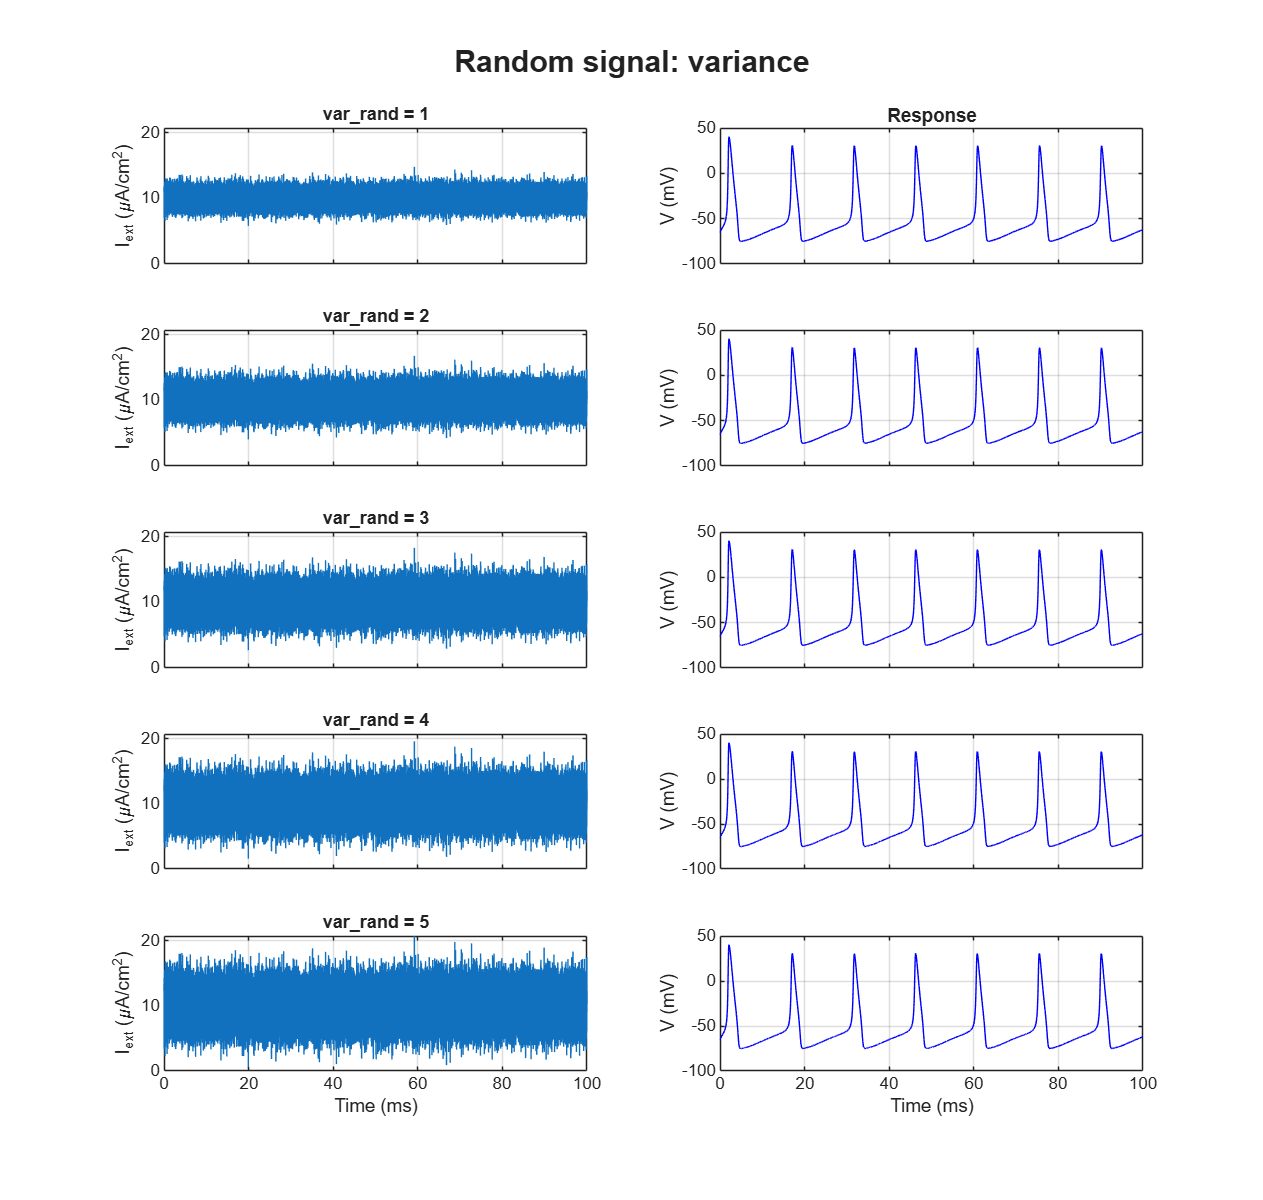

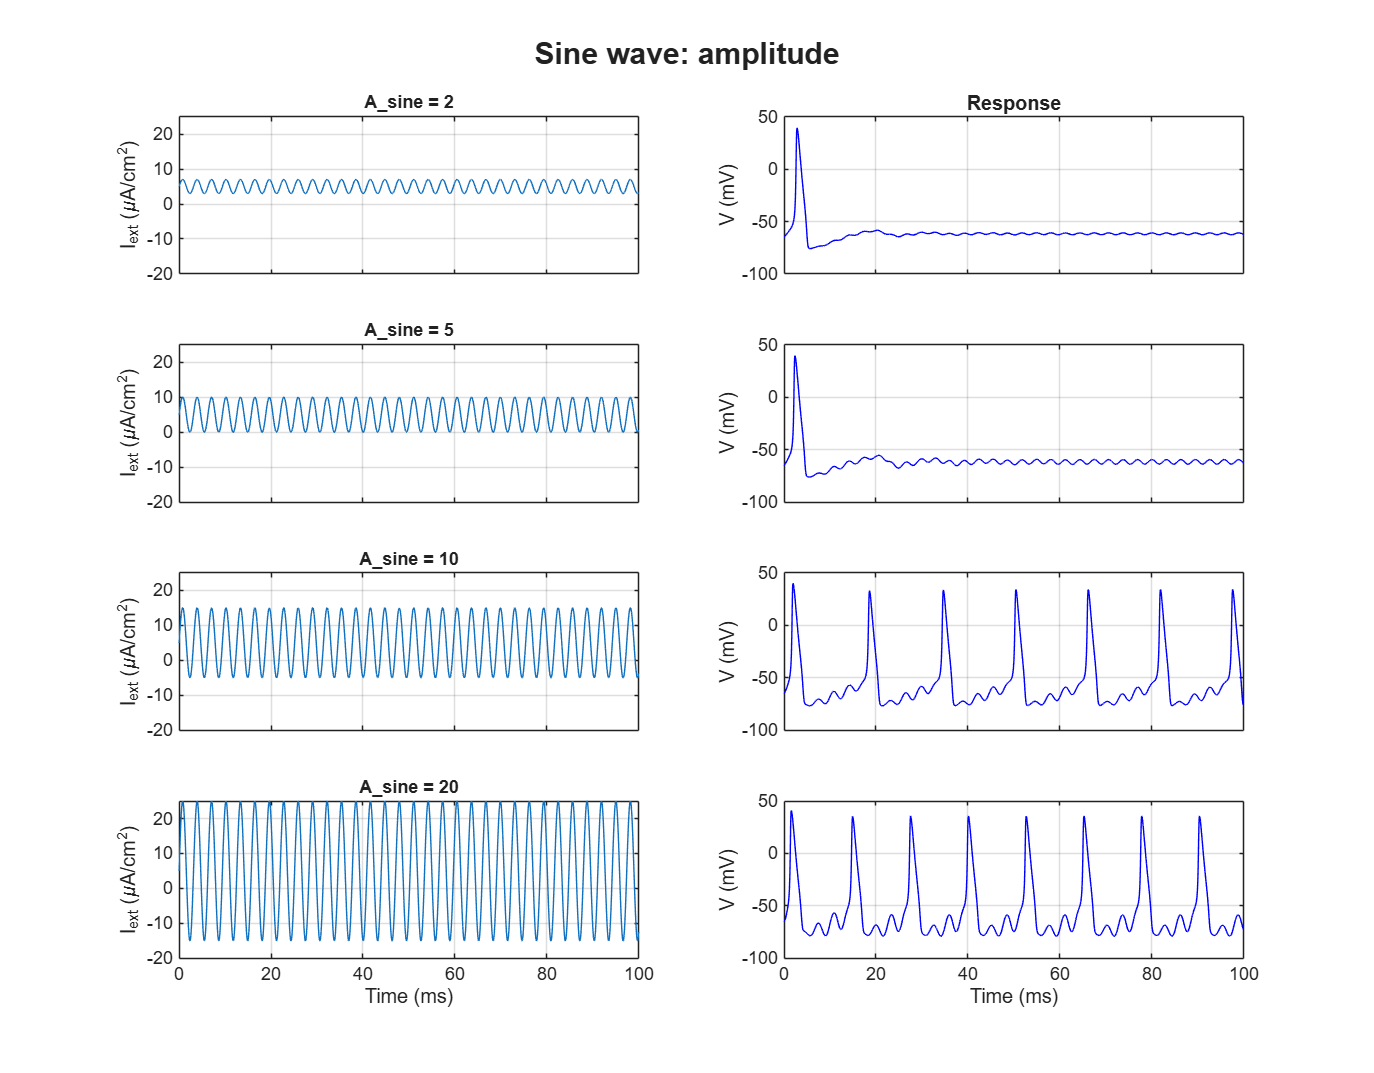

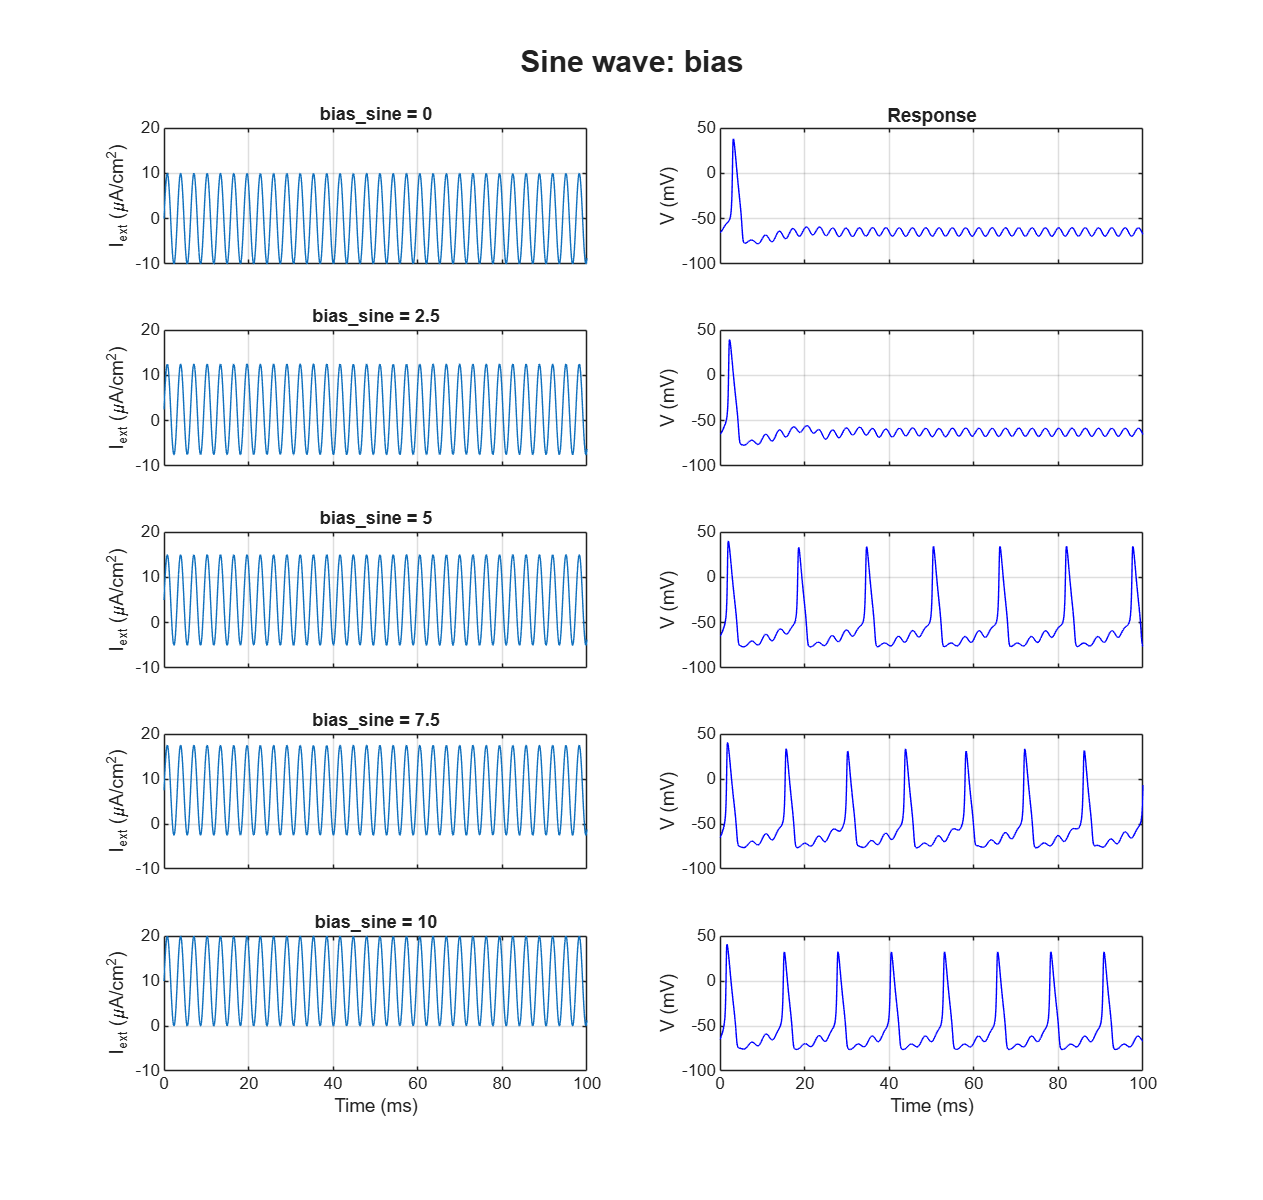

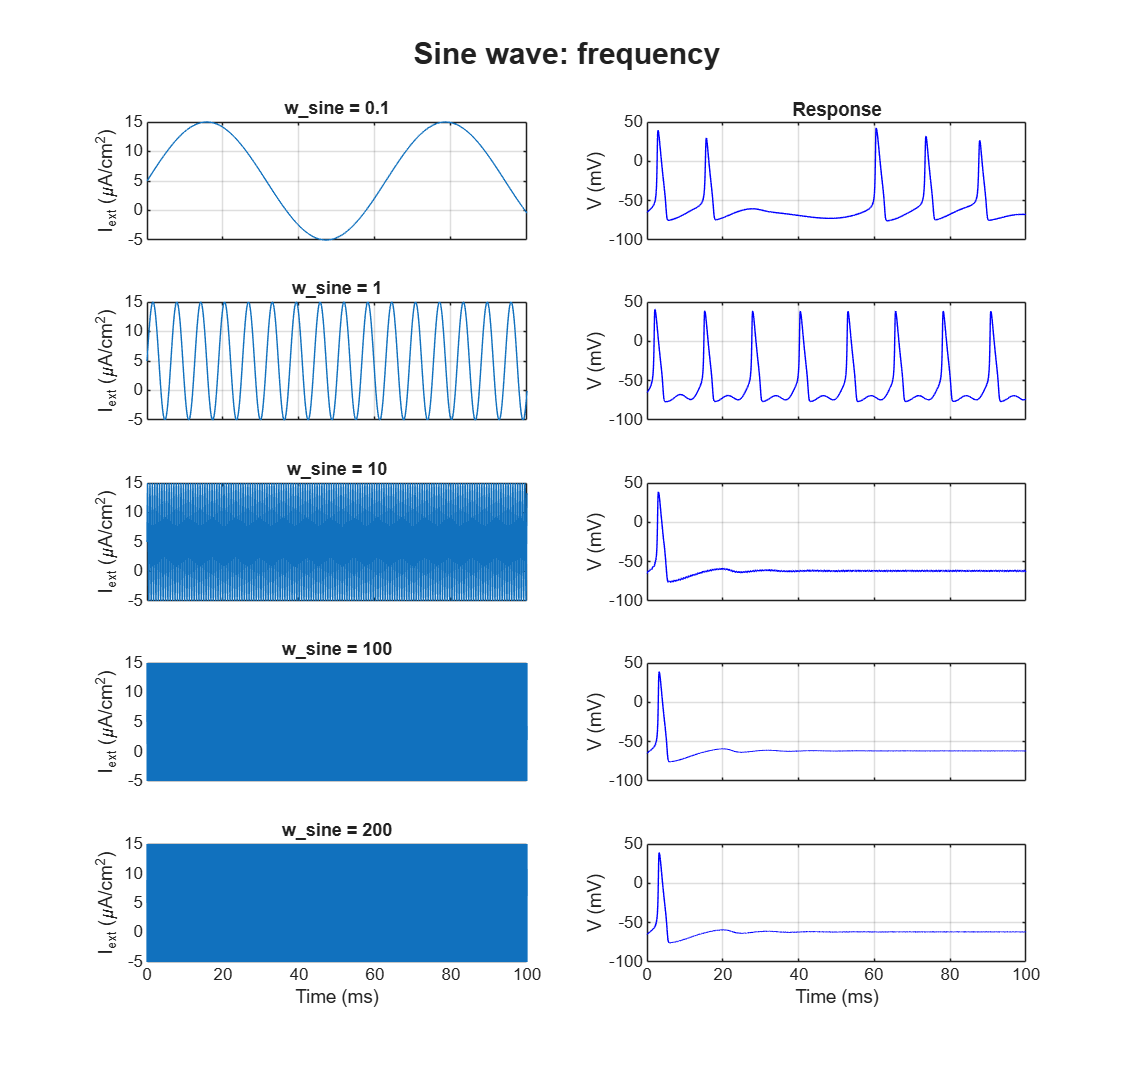

close all
Tstop = 100;     % Time [ms]

%% Parameter sweeps: each input type, one parameter at a time
% Each row: figure title | input selector | parameter name | values to test
sweeps = { 'Step signal: amplitude',   2, 'step_amplitude', [3, 5 15 30 100 200];
    'Random signal: variance',  3, 'var_rand',       [1 2 3 4 5];
    'Sine wave: amplitude',     5, 'A_sine',         [2 5 10 20];
    'Sine wave: bias',          5, 'bias_sine',      [0 2.5 5 7.5 10];
    'Sine wave: frequency',     5, 'w_sine',         [0.1 1 10 100 200] };

for s = 1:size(sweeps,1)
    figure_name    = sweeps{s,1};
    input_selector = sweeps{s,2};     % input used by the Multiport Switch
    pname = sweeps{s,3};              % parameter being swept
    vals  = sweeps{s,4};              % values of that parameter
    n = numel(vals);

    figure('Color','w','Name',figure_name,'Position',[100 50 1000 min(170*n+100, 950)])
    axI = gobjects(1,n);
    axV = gobjects(1,n);

    for i = 1:n

        % Default values (restored before every run, only pname changes)
        A_sine = 10;
        bias_sine = 5;
        w_sine = 2;
        step_amplitude = 30;     % from 0 to 200
        var_rand = 1;            % 1 to 5

        % Change the parameter being swept
        eval([pname ' = vals(i);']);

        % Simulate
        result = sim('circuit', 'StopTime', string(Tstop));

        % Get input current and membrane potential
        I = result.Iext.get(1).Values;
        V = result.V.get(1).Values;
        tI = I.Time(:);   Id = reshape(I.Data, numel(tI), []);   Id = Id(:,1);
        tV = V.Time(:);   Vd = reshape(V.Data, numel(tV), []);   Vd = Vd(:,1);

        % Left column: Input current (the swept parameter is in the title)
        axI(i) = subplot(n, 2, 2*i-1);
        plot(tI, Id);
        title(sprintf('%s = %g', strrep(pname,'_','\_'), vals(i)), 'FontSize', 9);
        ylabel('I_{ext} (\muA/cm^2)');
        grid on;

        % Right column: Membrane potential
        axV(i) = subplot(n, 2, 2*i);
        plot(tV, Vd, 'b');
        ylabel('V (mV)');
        grid on;

        % Time label only on the last row
        if i < n
            set(axI(i), 'XTickLabel', []);
            set(axV(i), 'XTickLabel', []);
        else
            xlabel(axI(i), 'Time (ms)');
            xlabel(axV(i), 'Time (ms)');
        end
    end

    title(axV(1), 'Response');
    sgtitle(figure_name, 'FontWeight', 'bold');

    linkaxes([axI axV], 'x');    % same time window in all panels
    linkaxes(axI, 'y');          % same input scale
    linkaxes(axV, 'y');          % same V scale, so responses are comparable
end

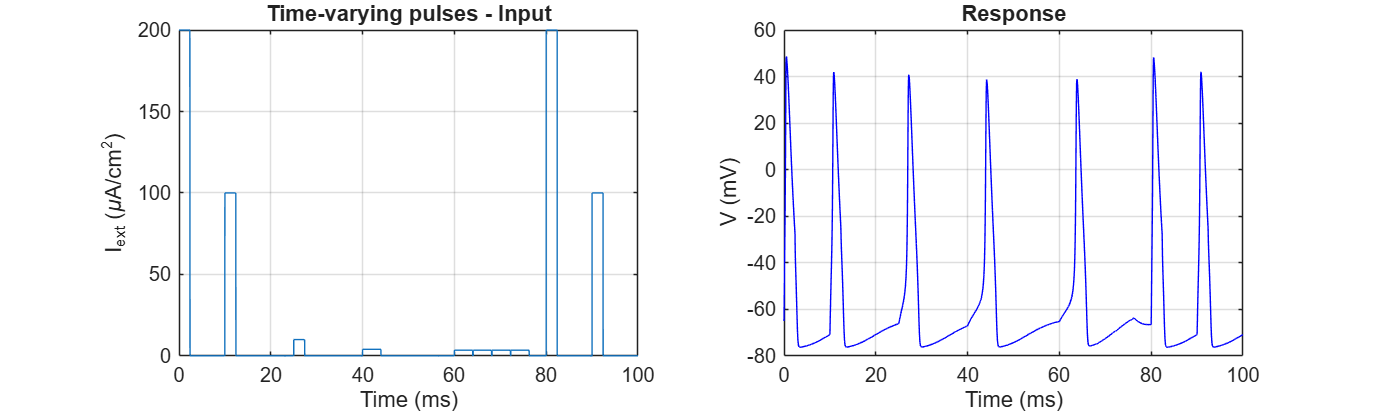

%% Time-varying pulses: single run (no parameters to vary)
input_selector = 4;
result = sim('circuit', 'StopTime', string(Tstop));

I = result.Iext.get(1).Values;
V = result.V.get(1).Values;
tI = I.Time(:);   Id = reshape(I.Data, numel(tI), []);   Id = Id(:,1);
tV = V.Time(:);   Vd = reshape(V.Data, numel(tV), []);   Vd = Vd(:,1);

figure('Color','w','Name','Time-varying pulses','Position',[100 50 1000 300]);

axI = subplot(1,2,1);
plot(tI, Id);
title('Time-varying pulses - Input');
xlabel('Time (ms)'); ylabel('I_{ext} (\muA/cm^2)'); grid on;

axV = subplot(1,2,2);
plot(tV, Vd, 'b');
title('Response');
xlabel('Time (ms)'); ylabel('V (mV)'); grid on;

linkaxes([axI axV], 'x');

**4- Study the response of V(t), IL(t), INa(t), IK(t), m(t), h(t), n(t). Generate appropriately labelled plots in MATLAB.**

% Using our favorite parameters from the inputs, we simulate them to obtain
% the results
Tstop = 100;     % Time [ms]

% Each row: name | input selector | parameter values used in that case
cases = { 'Step signal',        2;
    'Random signal',      3;
    'Sine wave',          5;
    'Time-varying pulses', 6};

case_names = cases(:,1);
results = cell(1, size(cases,1));

% Our chosen values
A_sine = 10;
bias_sine = 10;
w_sine = 1;
step_amplitude = 15;
var_rand = 3;
for k = 1:size(cases,1)
    % Input selector of this case
    input_selector = cases{k,2};

    % Simulate once and store
    results{k} = sim('circuit', 'StopTime', string(Tstop));
end

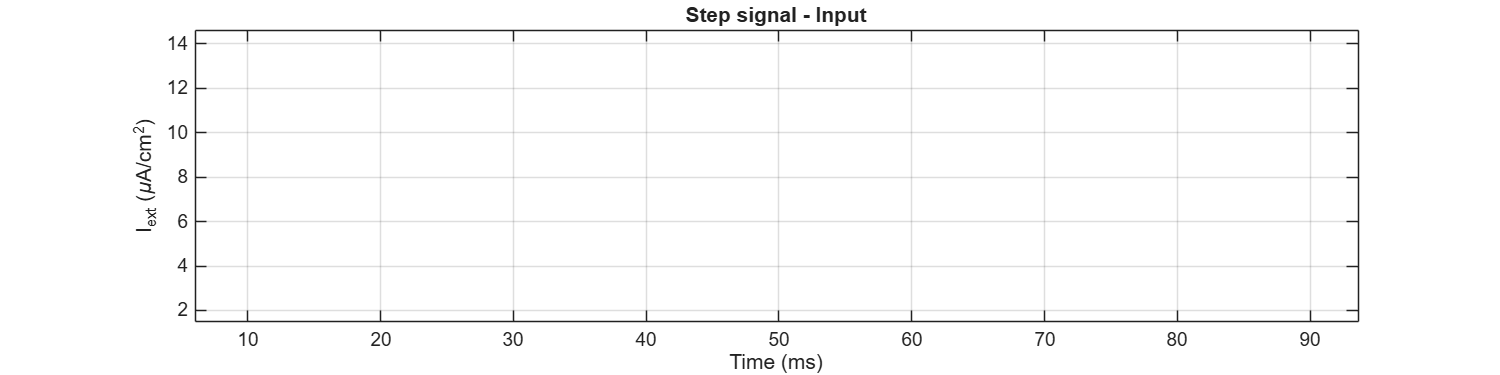

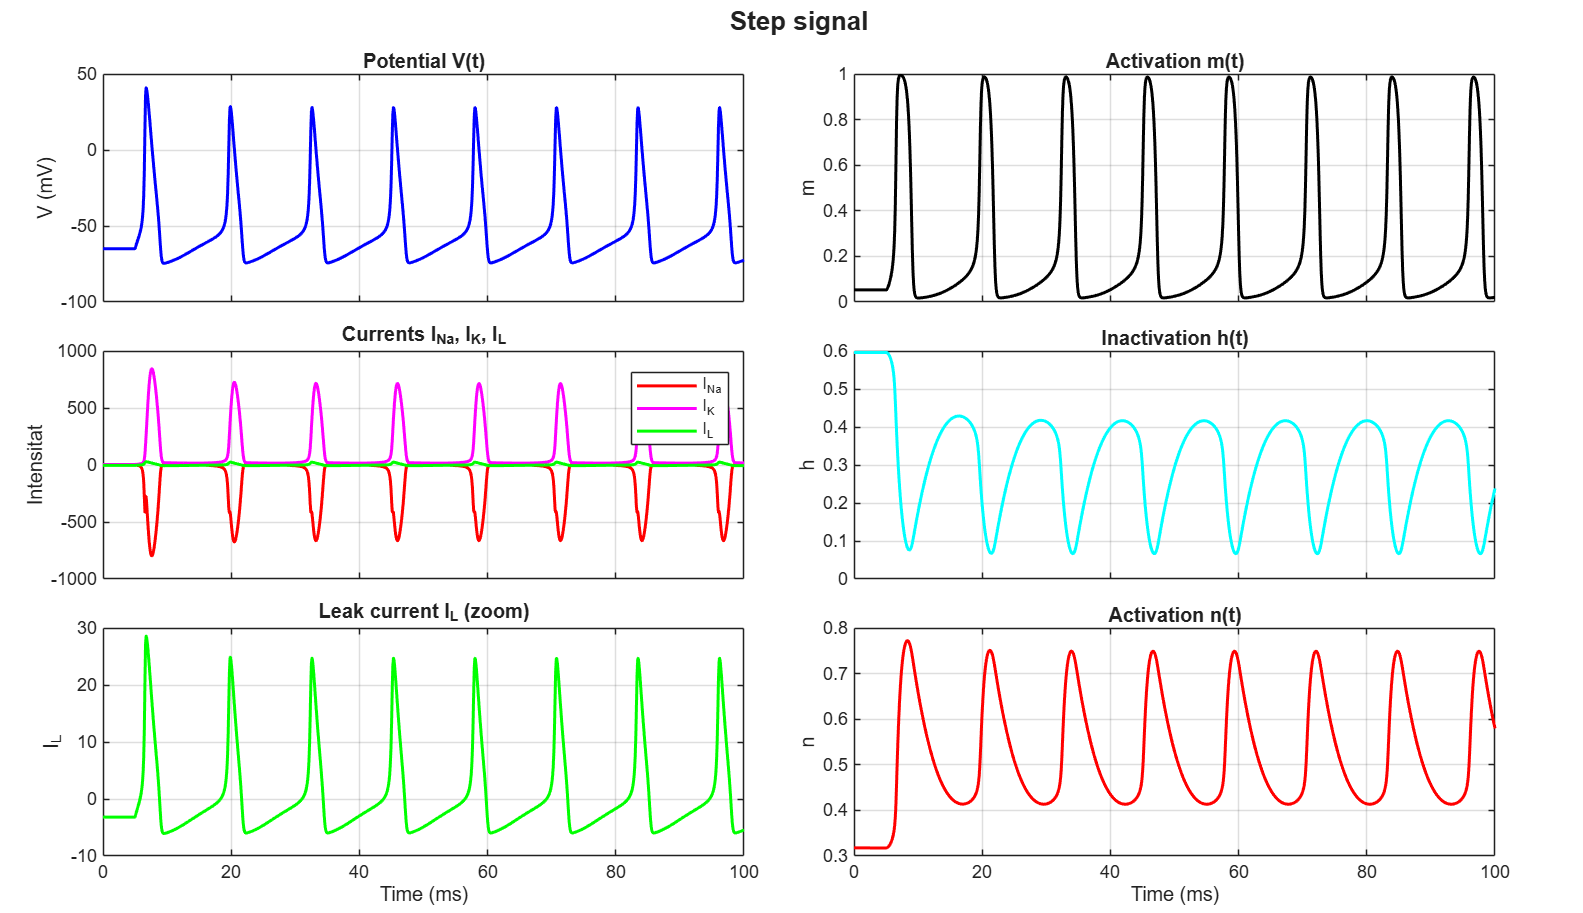

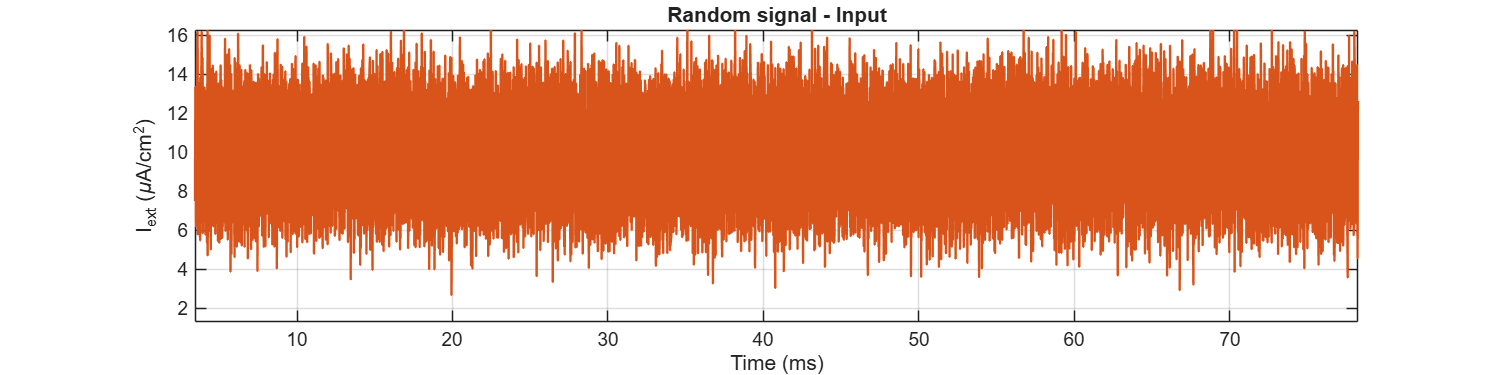

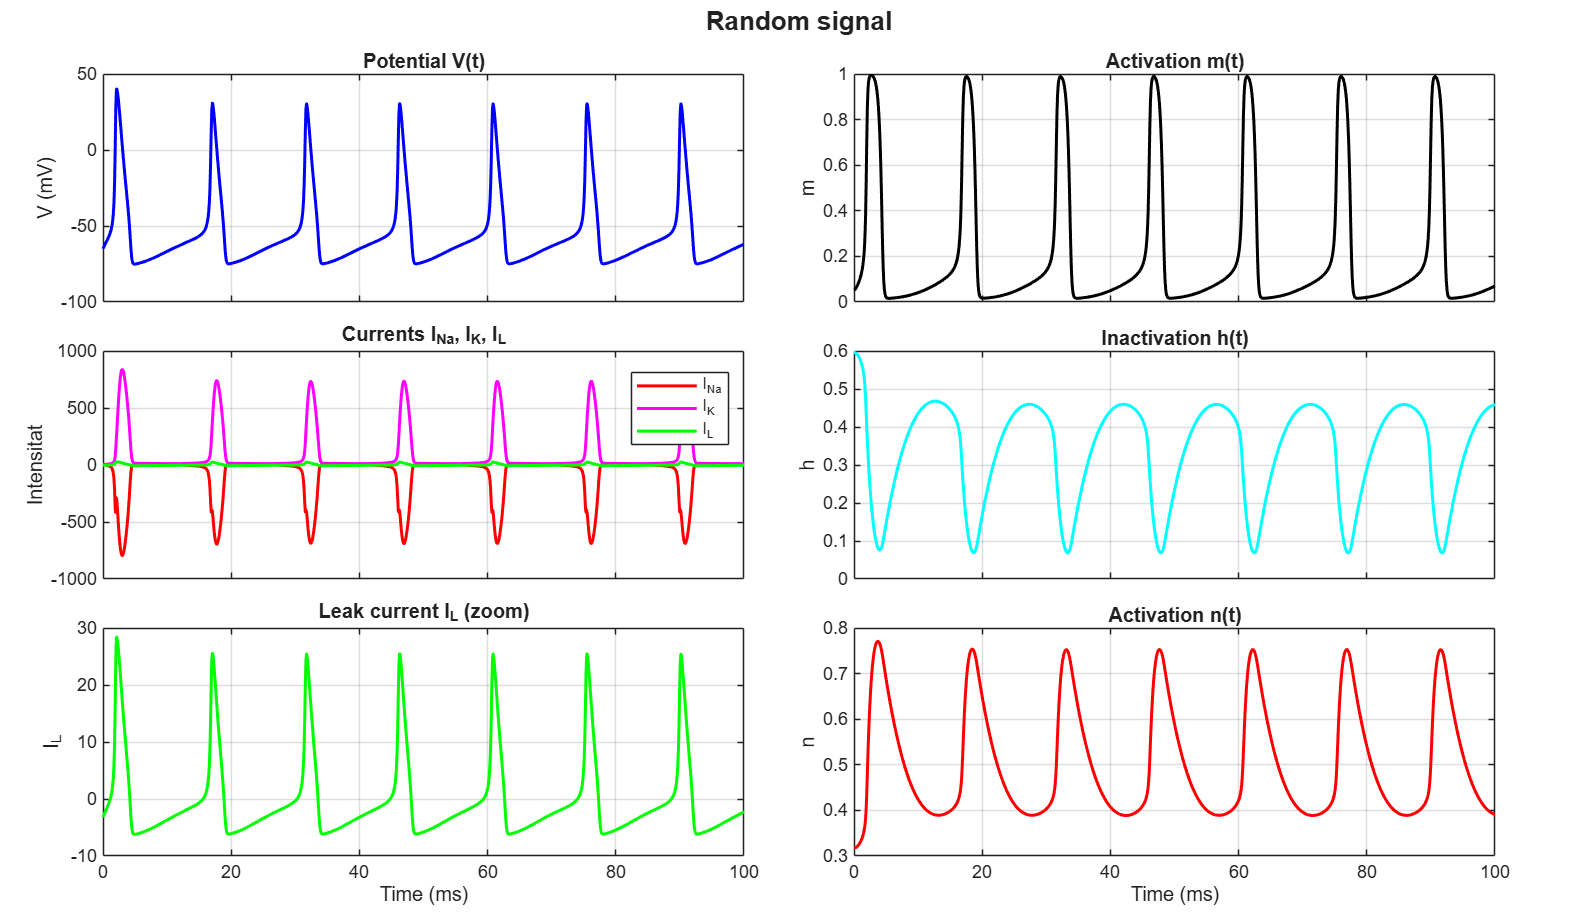

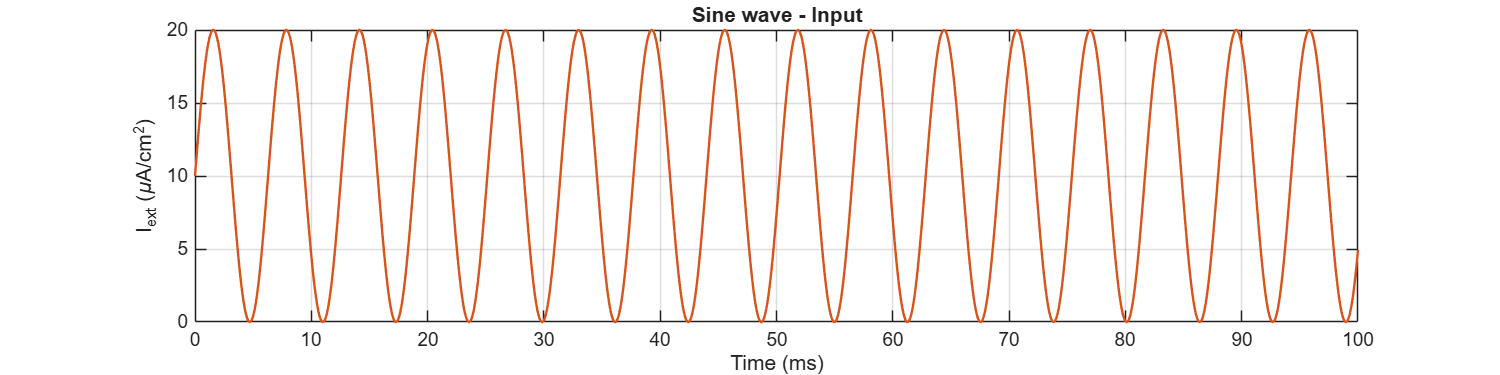

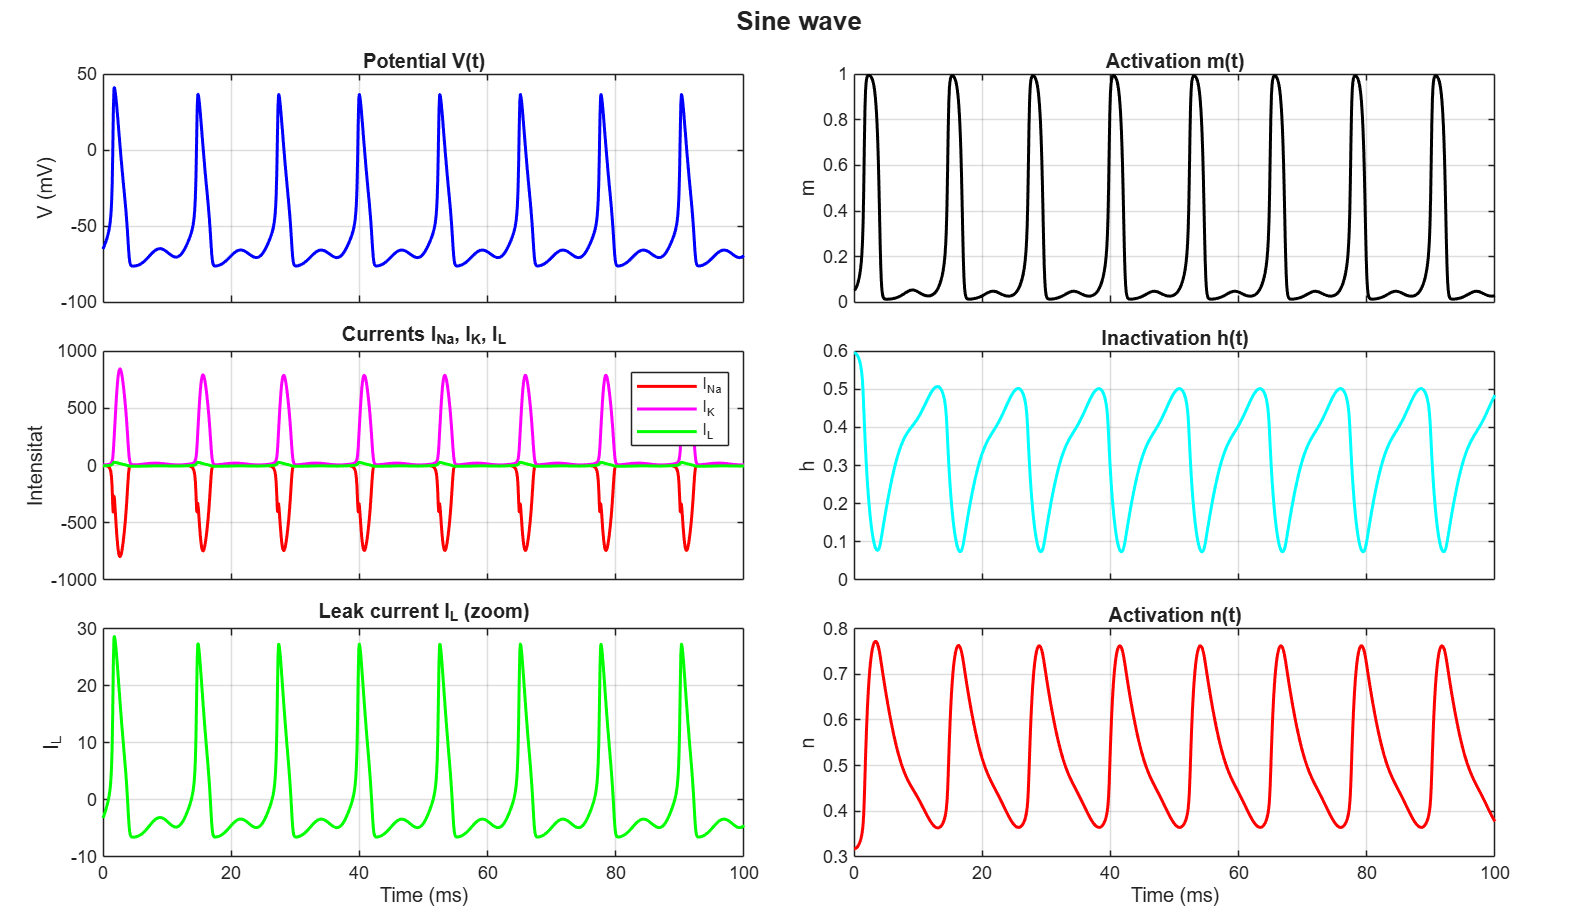

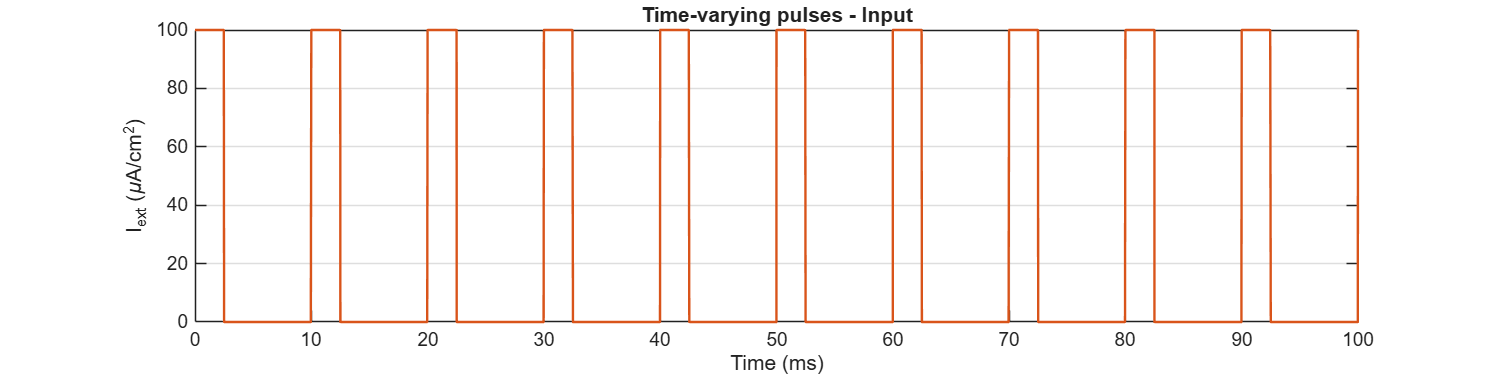

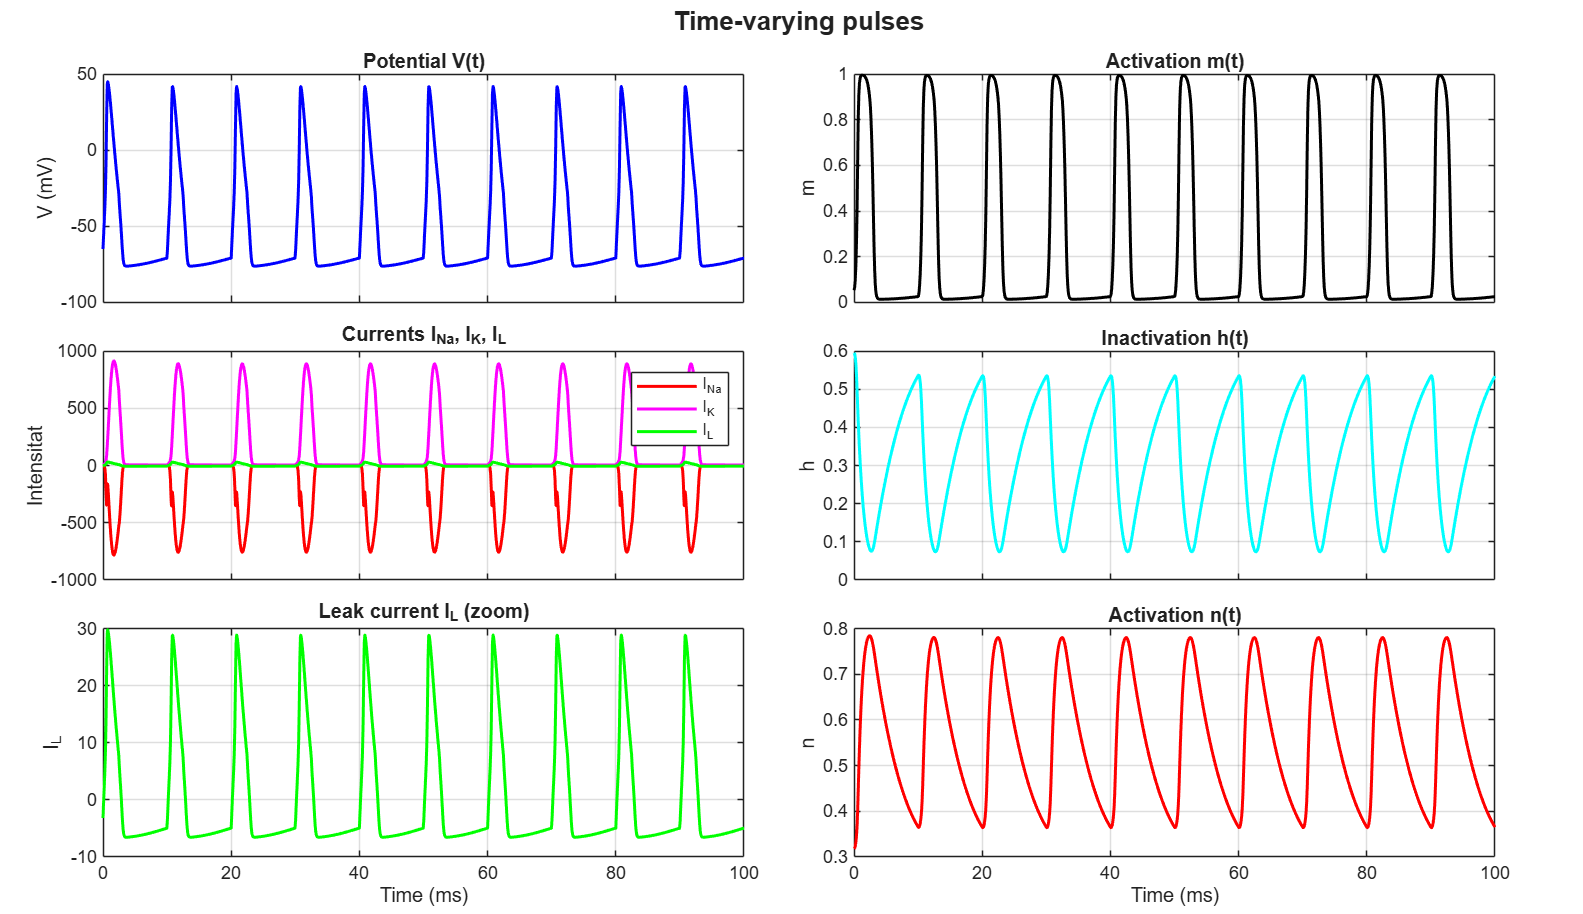

%% And plot them: input first, then responses
close all
for k = 1:numel(results)

    % --- Input current ---
    I  = results{k}.Iext.get(1).Values;
    tI = I.Time(:);
    Id = reshape(I.Data, numel(tI), []);
    Id = Id(:,1);

    figure('Color','w','Name',[case_names{k} ' - Input'], ...
        'Position',[100 100 1000 250]);
    plot(tI, Id, 'Color', [0.85 0.33 0.10], 'LineWidth', 1.2);
    title([case_names{k} ' - Input']);
    xlabel('Time (ms)'); ylabel('I_{ext} (\muA/cm^2)'); grid on;

    % --- Responses (V, currents, gating variables) ---
    plot_input_responses(results{k}, case_names{k});
end

**5- Discuss the results, compare them with real physiological recordings, and include explanatory figures of the neuronal membrane dynamics, providing links to all sources used.**

%% Pathological conditions with random input (original HH model)
close all

input_selector = 3;      % random signal
seed_rand = 1;           % same noise in every condition

%        name            Cm  gNa  gK  gl
cond = { 'Normal',        1, 120, 36, 0.3;
    'MS',            2, 120, 20, 0.5;
    'MS corrected',            2, 120, 36, 0.5;
    'Hyperkalemia',  1, 120, 40, 0.3;
    'LQTS',          1,  60, 25, 0.3;
    'LQTS corrected',          1,  120, 25, 0.3 };
names = cond(:,1);
nC = numel(names);

%% Simulations
results = cell(1, nC);
IC = zeros(nC, 4);                         % V0, m0, h0, n0
Tstop = 200;

for c = 1:nC
    Cm = cond{c,2};  GNa = cond{c,3};  GK = cond{c,4};  Gl = cond{c,5};
    V0 = -65; m0 = 0.05; h0 = 0.6; n0 = 0.32; 
    mean_rand = 0;          
    var_rand  = 0;          
    out = sim('circuit', 'StopTime', string(Tstop));    
    V_ = out.V.get(1).Values;  m_ = out.m.get(1).Values;
    h_ = out.h.get(1).Values;  n_ = out.n.get(1).Values;
    IC(c,:) = [V_.Data(end) m_.Data(end) h_.Data(end) n_.Data(end)];
    mean_rand = 10;          % tune so the Normal case fires sporadically
    var_rand  = 3;           % within 1 to 5
    results{c} = sim('circuit', 'StopTime', string(Tstop/4));
end

%% Initial conditions 
Condition = names;
V0 = IC(:,1); m0 = IC(:,2); h0 = IC(:,3); n0 = IC(:,4);
table(Condition, V0, m0, h0, n0)

ans = 6×5 table
        Condition           V0          m0         h0         n0   
    __________________    _______    ________    _______    _______

    {'Normal'        }        -65    0.052934    0.59611    0.31768
    {'MS'            }    -63.107    0.064163    0.51894    0.35299
    {'MS corrected'  }    -63.594    0.062387    0.54627    0.33942
    {'Hyperkalemia'  }    -65.388    0.050562    0.60961    0.31175
    {'LQTS'          }    -64.283    0.057582    0.57084    0.32872
    {'LQTS corrected'}    -63.472    0.063281    0.54187    0.34134

	Get insights using Copilot


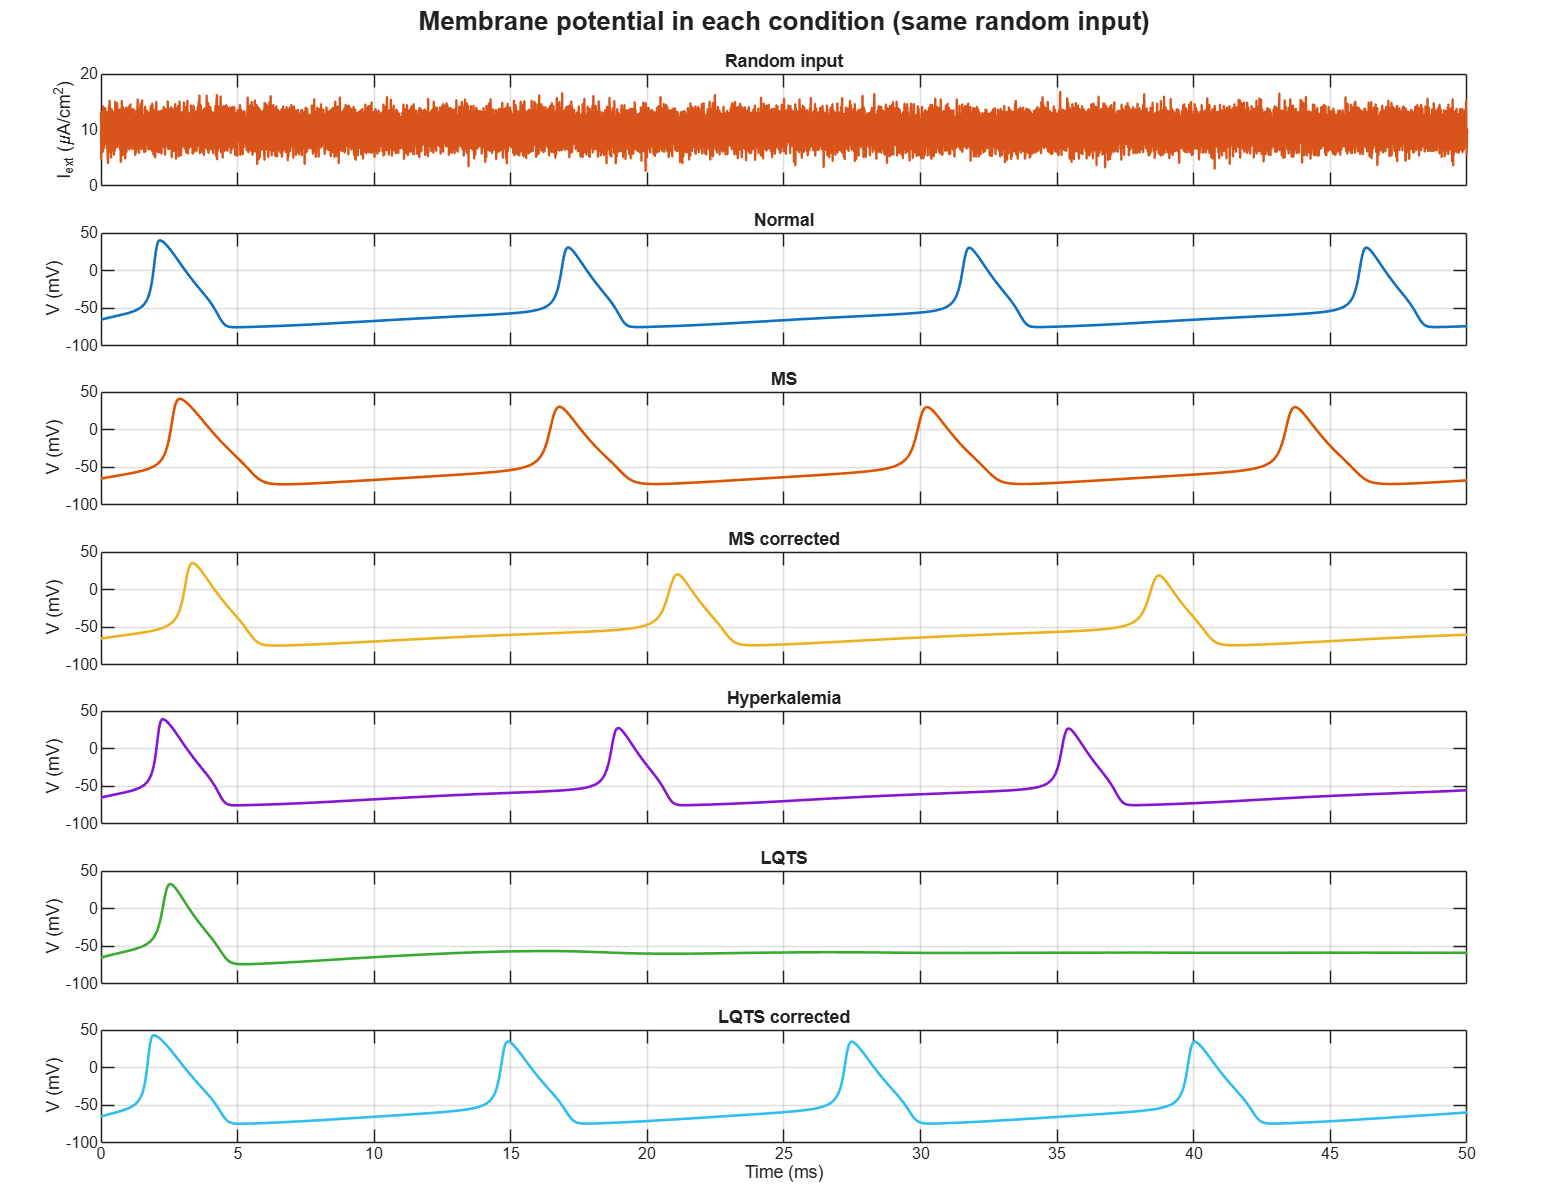

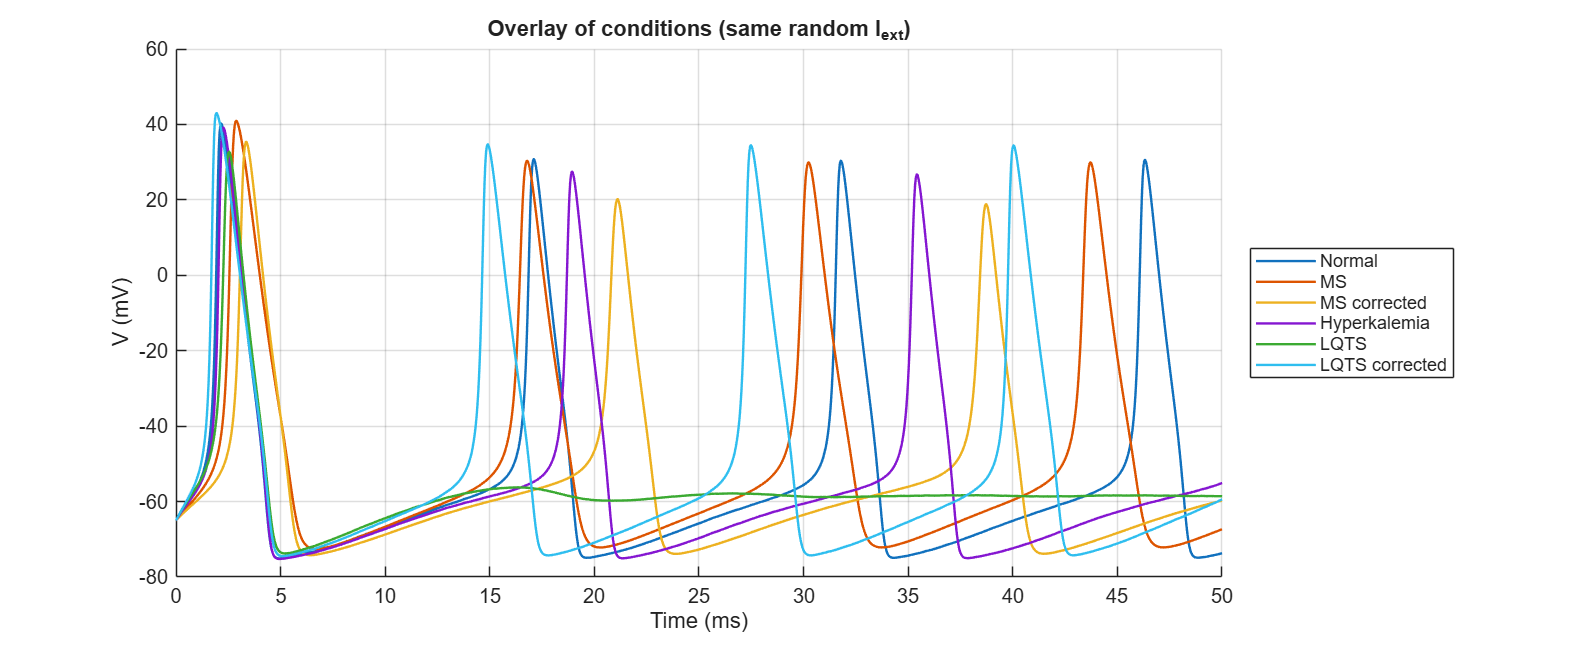

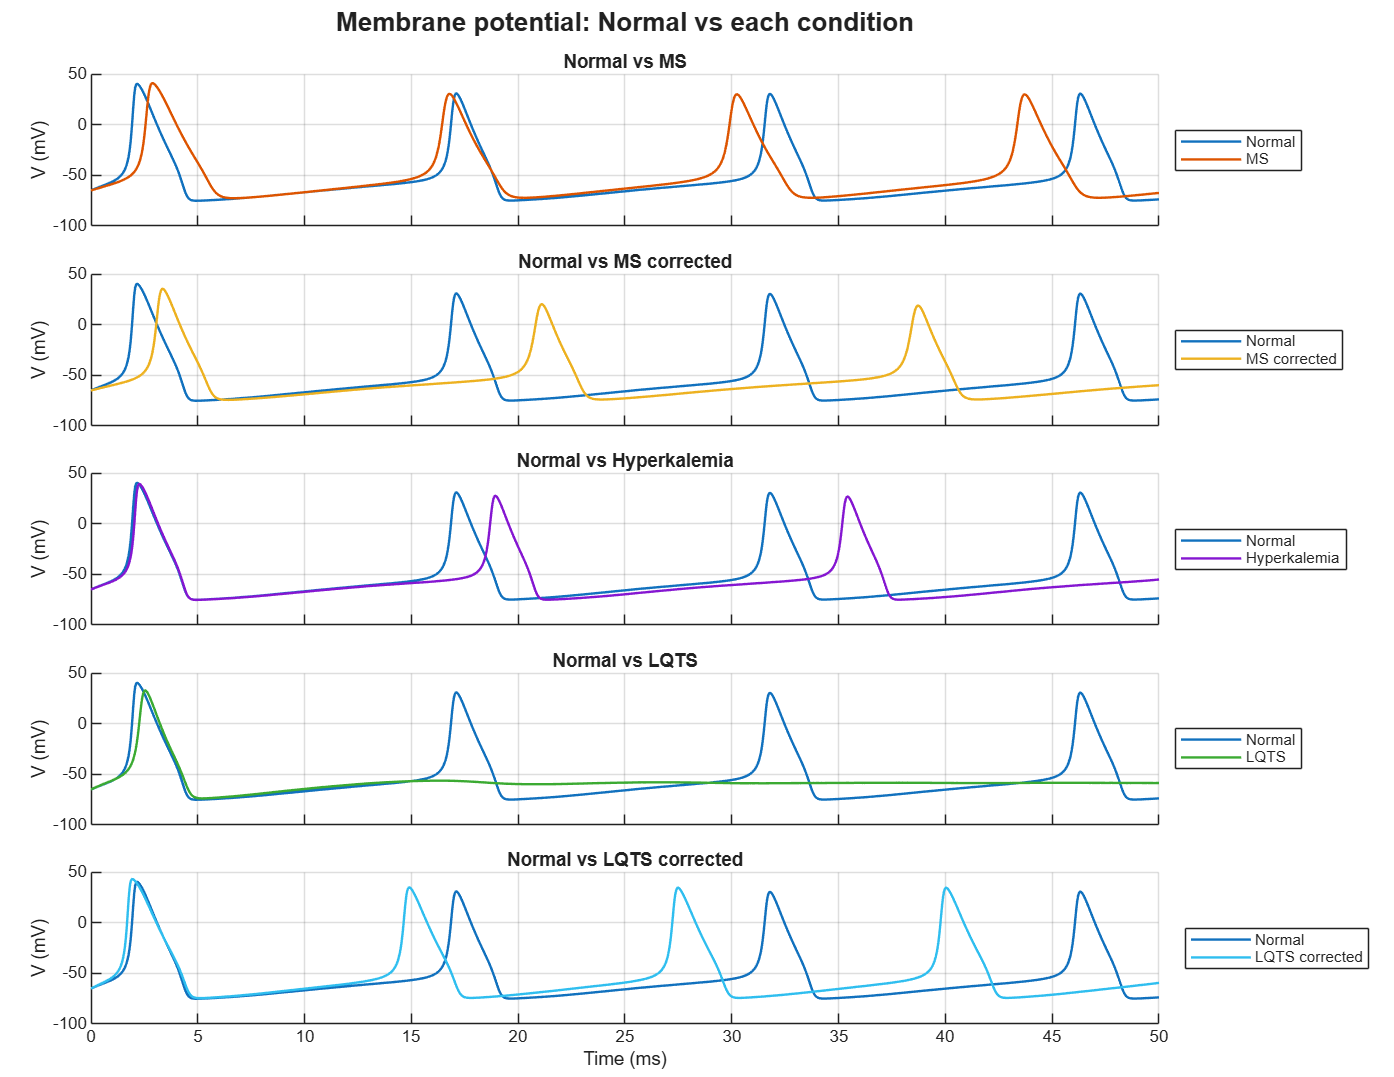

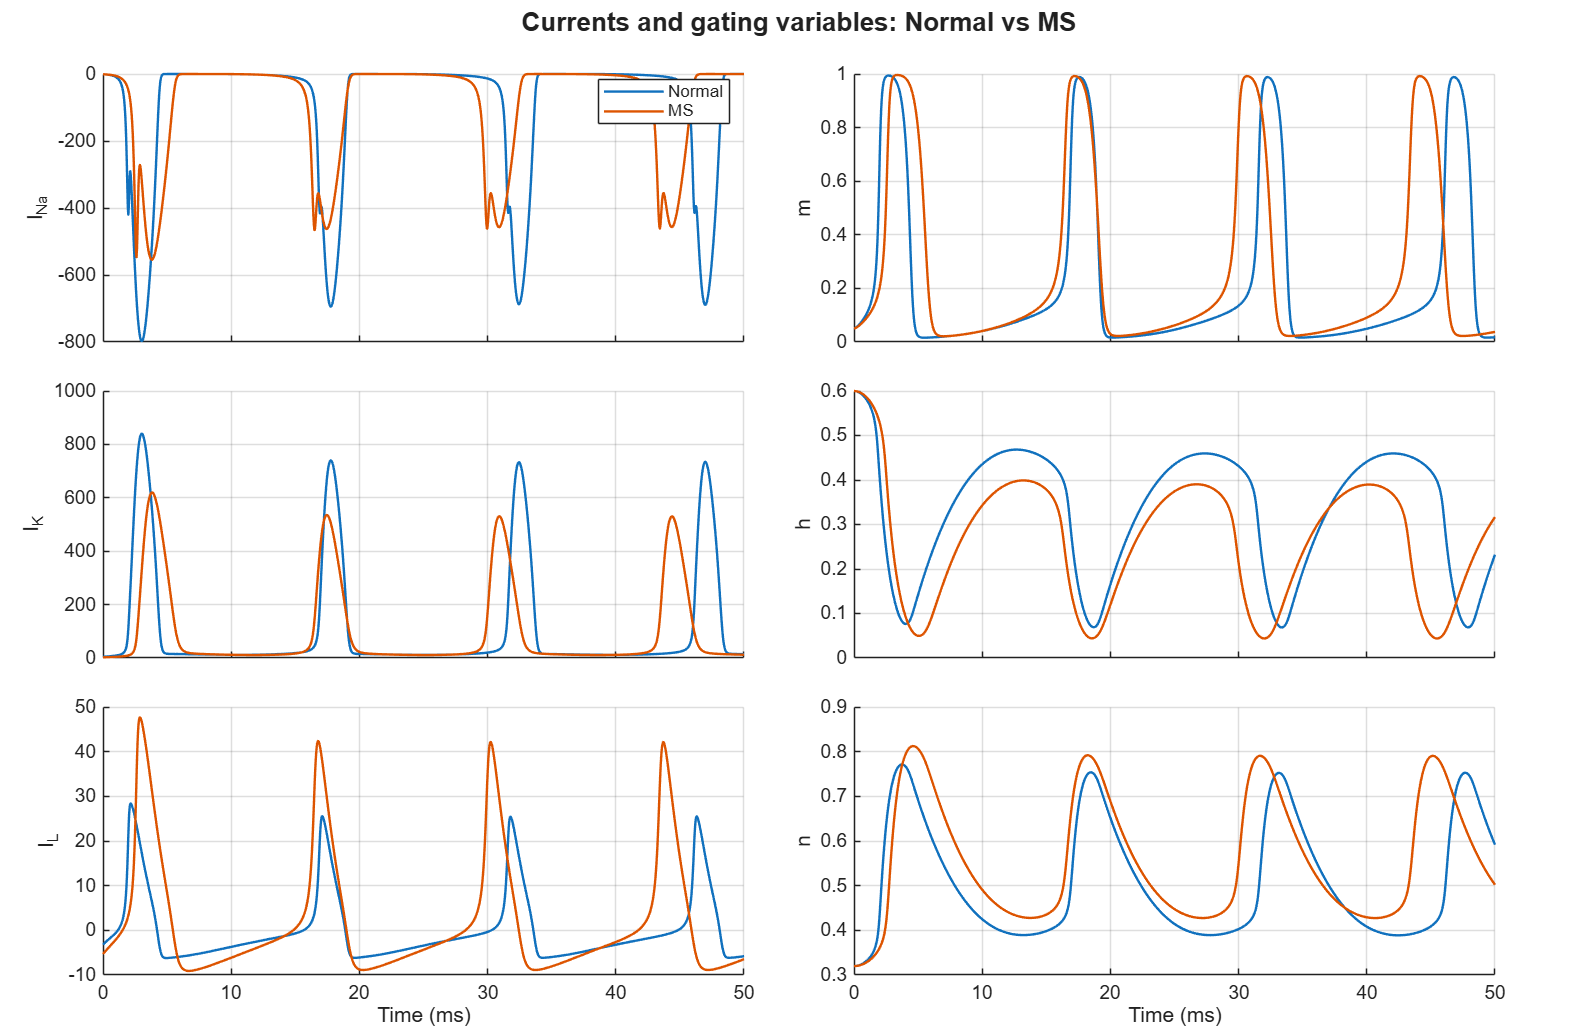

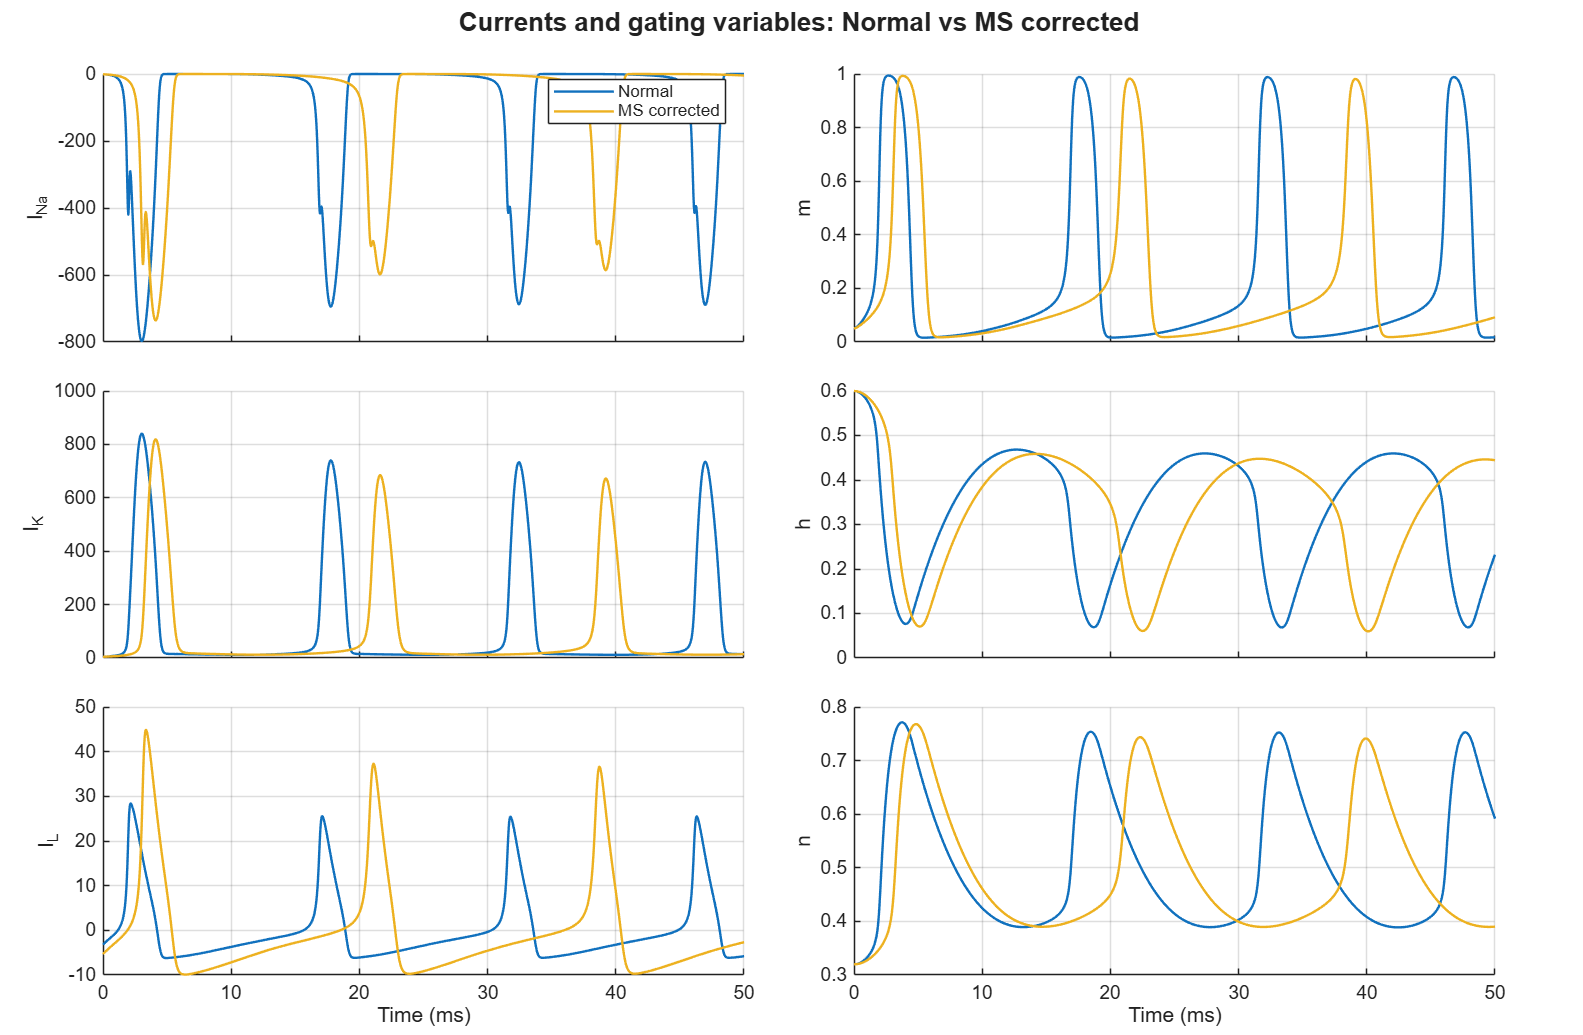

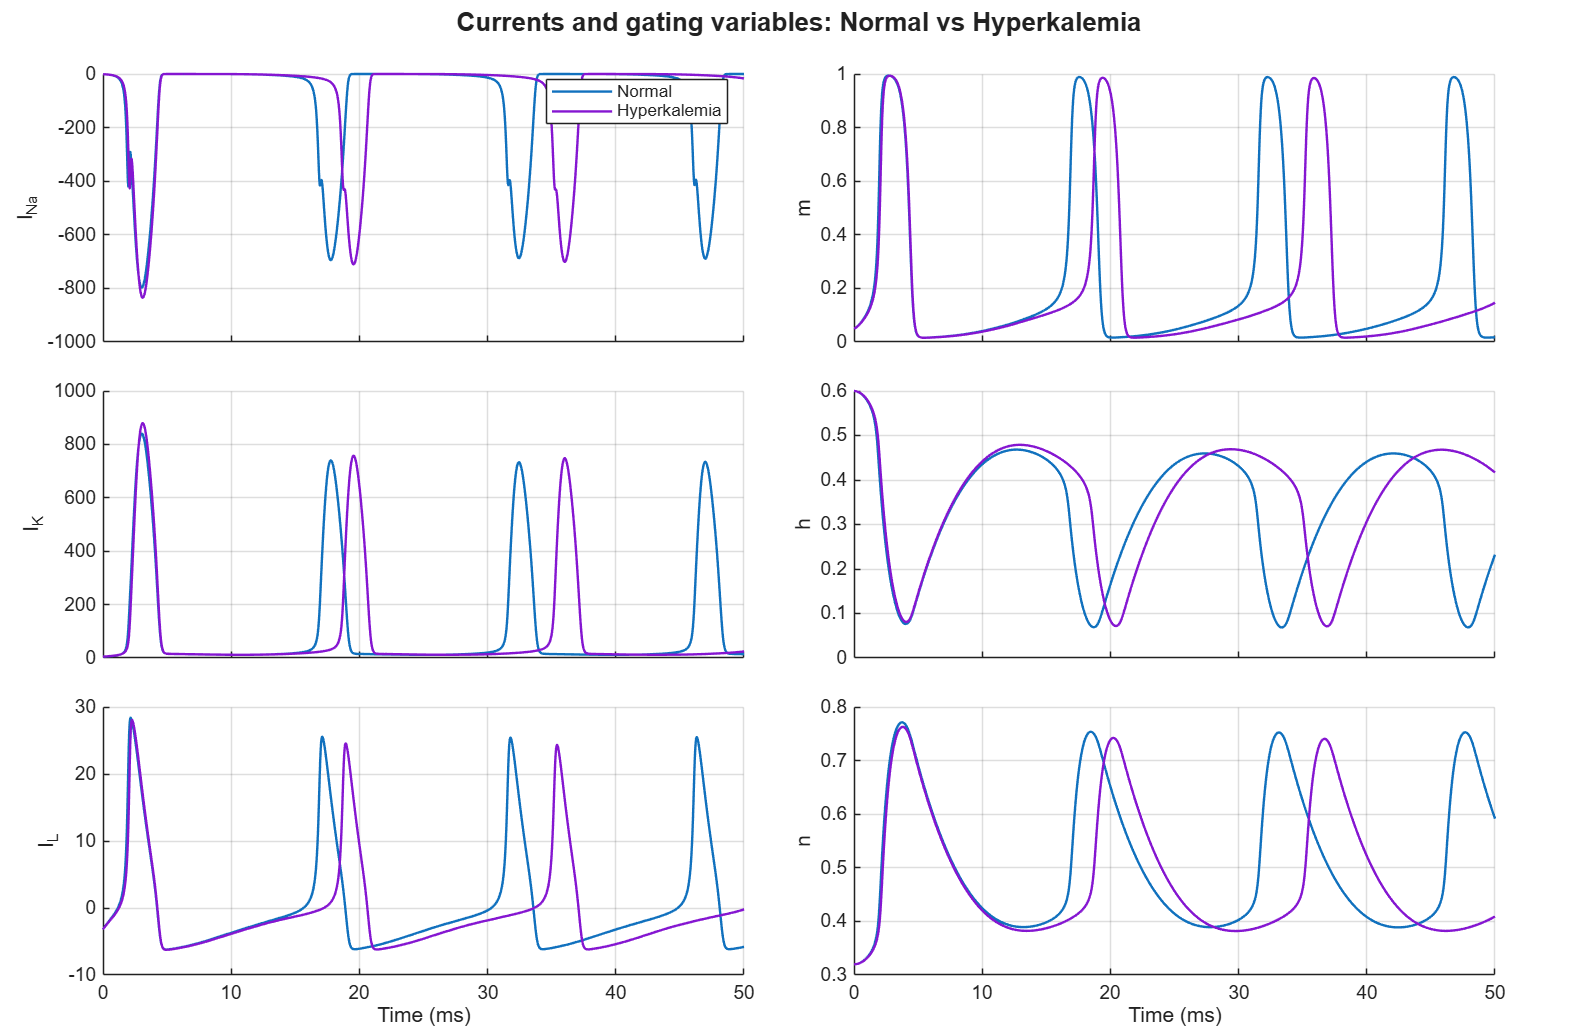

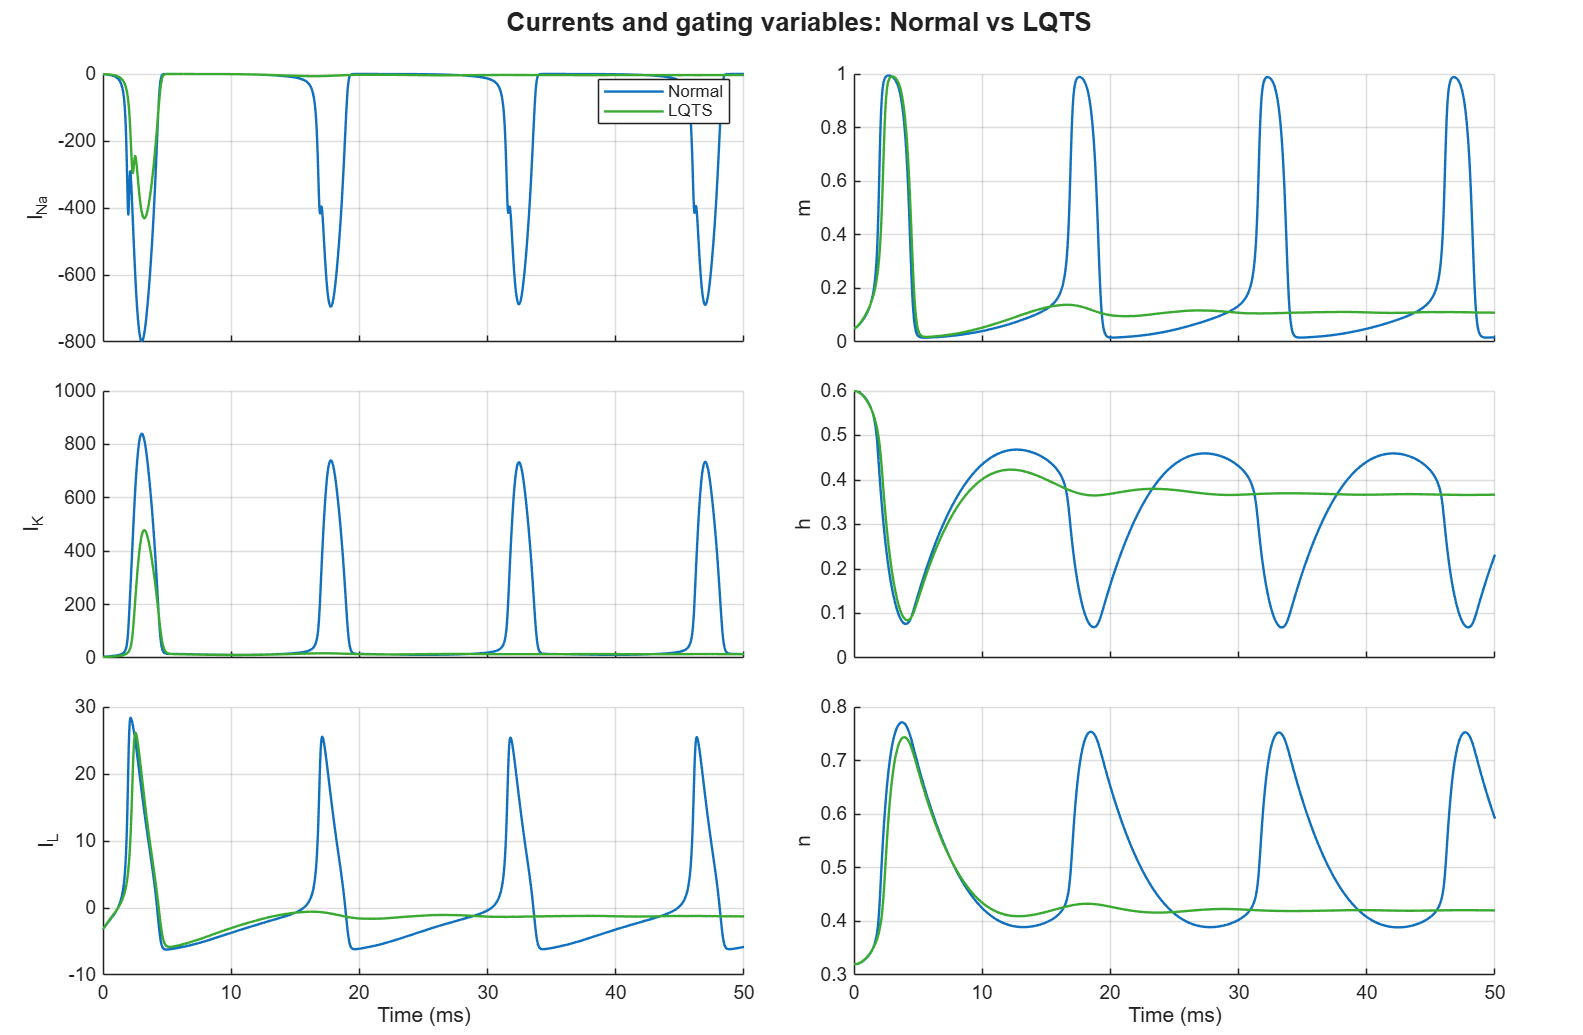

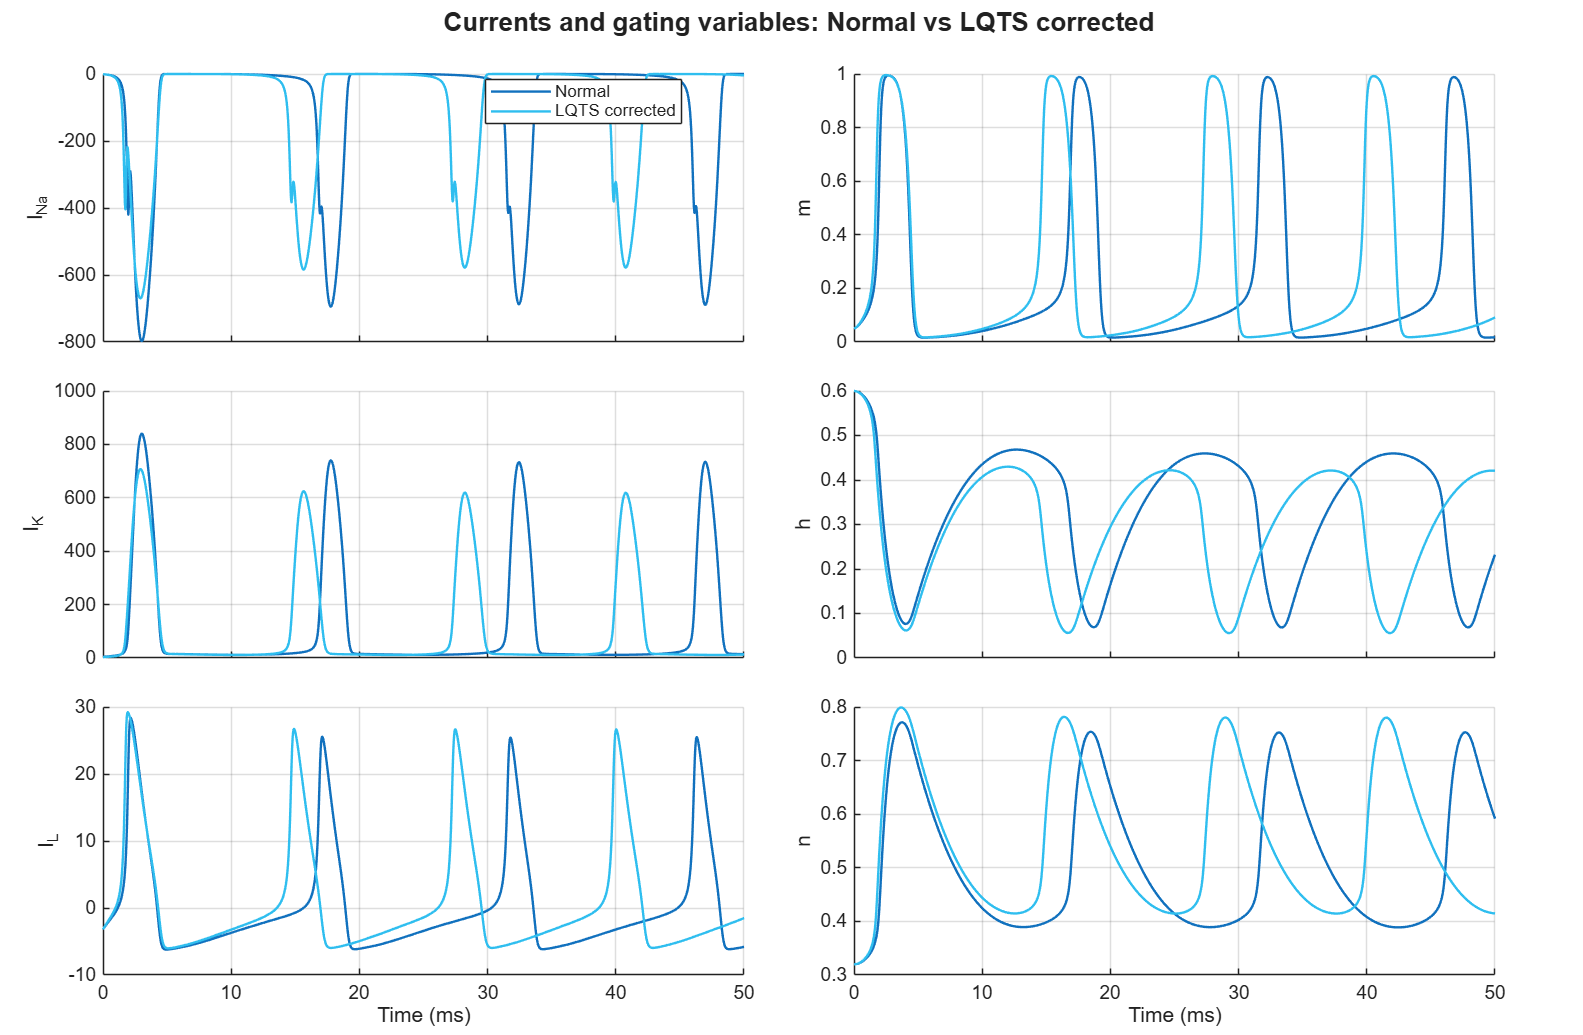

%% Plots
plot_pathologies(results, names);